# This is MATLAB codes of the article:				

***General Solutions for Poroelastic Equations with Viscous Stress*****, by M. Moradi and Ehssan Nazockdast **

## ***1- Solving  the equations of a rigid sphere moving with constant  force in a poroelastic medium***

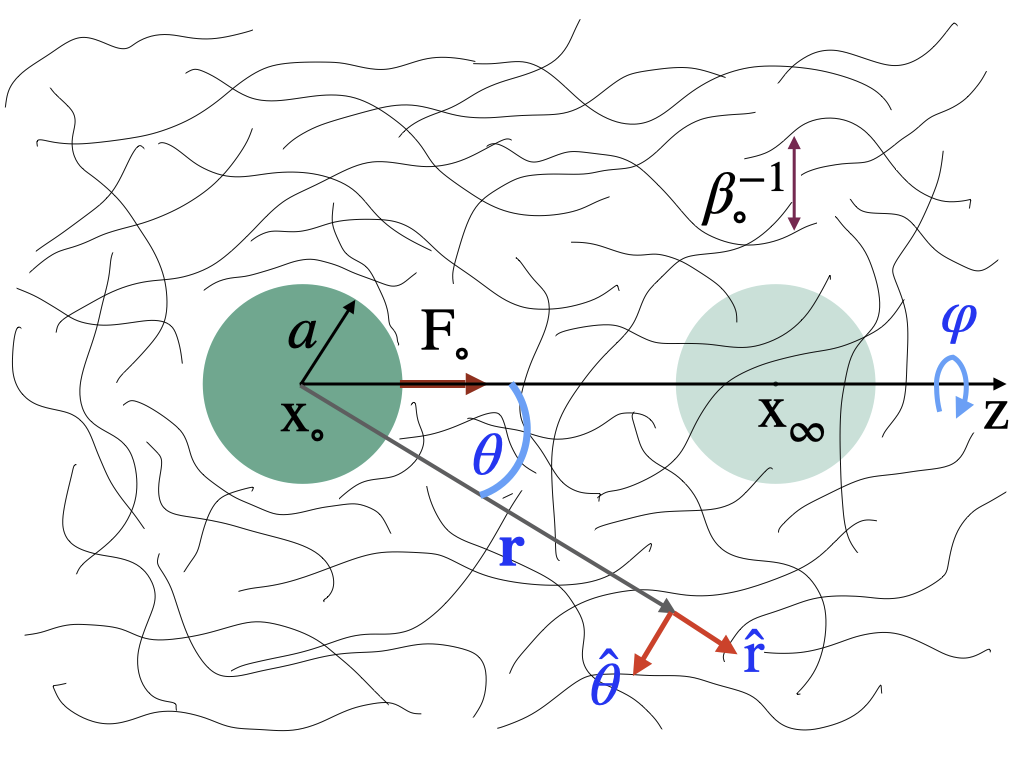

The General solutions of poroelastic equations in axisymmetric geometry is:


$$$v_{r,f}^{(\mathrm{d})} =    \frac{\cos\theta}{\eta +G} \Bigg[  - \frac{2}{r^3} B_{2}^{-} + \frac{2G}{\beta r} {\mathtt{k}}_1 (\beta r) {B '}_{1}^{-} + \left( \frac{1}{r} + \frac{2G}{{\eta}_{\varepsilon} {\beta}^{2}} \frac{1}{r^3}  \right) D_{1}^{-}  - \frac{ \varepsilon (\eta +G) }{{\alpha}_{\varepsilon}^2} E_{1}^{-} \frac{\mathrm{d}}{\mathrm{d}r} {\mathtt{k}}_1 ({\alpha}_{\varepsilon} r)  \Bigg]  $$$



$$$ v_{\theta ,f}^{(\mathrm{d})} =     \frac{-\sin\theta}{\eta +G}   \Bigg[ \frac{1}{r^3} B_{2}^{-} + \frac{G}{\beta} \left( \frac{1}{r} {\mathtt{k}}_1 (\beta r) + \frac{\mathrm{d}}{\mathrm{d} r} {\mathtt{k}}_1 (\beta r)  \right) {B'}_{1}^{-} + \left( \frac{1}{2 r} - \frac{G}{{\eta}_{\varepsilon} {\beta}^{2}} \frac{1}{r^3}  \right) D_{1}^{-}  - \frac{ \varepsilon (\eta +G) }{{\alpha}_{\varepsilon}^2} E_{1}^{-} \frac{1}{r} {\mathtt{k}}_1 ({\alpha}_{\varepsilon} r)  \Bigg] $$$



$$$v_{r,n}^{(\mathrm{d})} =    \frac{\cos\theta}{\eta +G}  \Bigg[ - \frac{2}{r^3} B_{2}^{-} - \frac{2\eta }{\beta r} {\mathtt{k}}_1 (\beta r) {B '}_{1}^{-} + \left( \frac{1}{r} - \frac{2\eta}{{\eta}_{\varepsilon} {\beta}^{2}} \frac{1}{r^3}  \right) D_{1}^{-}  - \frac{G + \eta}{{\alpha}_{\varepsilon}^2} E_{1}^{-} \frac{\mathrm{d}}{\mathrm{d}r} {\mathtt{k}}_1 ({\alpha}_{\varepsilon} r)   \Bigg]  $$$



$$$v_{\theta ,n}^{(\mathrm{d})} =     \frac{-\sin\theta}{\eta +G}  \Bigg[   \frac{1}{r^3} B_{2}^{-} - \frac{\eta}{\beta} \left( \frac{1}{r} {\mathtt{k}}_1 (\beta r) + \frac{\mathrm{d}}{\mathrm{d} r} {\mathtt{k}}_1 (\beta r)  \right) {B'}_{1}^{-} + \left( \frac{1}{2 r} + \frac{\eta}{{\eta}_{\varepsilon} {\beta}^{2}} \frac{1}{r^3}  \right) D_{1}^{-}  - \frac{G+\eta}{{\alpha}_{\varepsilon}^2} E_{1}^{-} \frac{1}{r} {\mathtt{k}}_1 ({\alpha}_{\varepsilon} r)   \Bigg] $$$


We want to find the coefficients $B_{2}^{-}$, $${B}_{1}^{\prime -}$$, $${D}_{1}^{-}$$, and $E_{1}^{-}$, so that they satisfy no-slip BCs on the surface of the sphere: $${\mathbf{v}}_{f ,n} (r=a)= \mathrm{U} \hat{\mathbf{z}}$$ . Here, $$\mathrm{U}= \mathrm{U}(s)$$ is the time-dependent velocity of the sphere, which we take it as known, for now.

clc; clear;
syms alpha beta beta0 eta s a r U G B BP D E tau eta_eps eps alpha_eps tau_eps 
% introducing modified spherical Bessel function K1, and it's derivative:
K1_alpha=(exp(-alpha_eps*r))*(1/(alpha_eps*r) + 1/(alpha_eps^2*r^2));
K1_beta=(exp(-beta*r))*(1/(beta*r) + 1/(beta^2*r^2));
DK1_alpha=simplify(diff(K1_alpha,r));
DK1_beta=simplify(diff(K1_beta,r));

% velocity fields of fluid and network in terms of uknowns B, BP, D, and E:
% (see Eqs.(3-2) in the main text) 
vrf = simplify( -U - (2/(eta+G))*(1/r^3)*B + ((2*G/(eta+G))*(1/(beta*r)))*(K1_beta)*BP  + ...
                    (1/(eta+G))*(1/r)*D + (2*G/(beta^2 *r^3))*(1/((eta_eps)*(eta+G)))* D ...
                    -(eps/(alpha_eps^2))*(DK1_alpha)*E   ) ;
vrf_a=simplify(subs(vrf,r,a));

vthf = simplify(U - (1/(eta+G))*(1/r^3)*B - ((G/(eta+G))*(1/(beta)))*(K1_beta/r + DK1_beta)*BP  - ...
                    (1/(eta+G))*(1/(2*r))*D + (1/(beta^2 *r^3))*(G/((eta_eps)*(eta+G)))* D   ...
                    +(eps/(alpha_eps^2))*(K1_alpha/r)*E   );
vthf_a=simplify(subs(vthf,r,a));

vrn = simplify( -U - (2/(eta+G))*(1/r^3)*B - (((2*(eta))/(eta+G))*(1/(beta*r)))*(K1_beta)*BP  + ...
                    (1/(eta+G))*(1/r)*D - ( 2/(beta^2 *r^3))*(1/(eta+G) )*(eta/eta_eps)* D  ...
                      - (1/(alpha_eps^2))*E*(DK1_alpha) ) ;
vrn_a=simplify(subs(vrn,r,a));

vthn = simplify(U  - (1/(eta+G))*(1/r^3)*B + (((eta)/(eta+G))*(1/(beta)))*(K1_beta/r + ...
                     DK1_beta)*BP  -  (1/(eta+G))*(1/(2*r))*D - (1/(beta^2 *r^3))*(1/(eta+G))*(eta/eta_eps)* D ...
                    + (1/(alpha_eps^2))*E*(K1_alpha/r)    );
vthn_a=simplify(subs(vthn,r,a));

% no-slip BCs on the surface of sphere:
eqns = [ vrf_a == 0 , vthf_a == 0 , ...
              vrn_a == 0 , vthn_a == 0  ];
% Solving the equations to find unknowns B, BP, D, and E:        
S = solve(eqns,B,BP, D, E);

B0 = simplify(S.B); BP0 = simplify(S.BP); 
D0 = simplify(S.D); E0 = simplify(S.E);
%%%%%%%%%%%%%%%%%%     Answer:   %%%%%%%%%%%%%%%%
% B = (U*a*(G + eta)*(12*G + 12*eps*eta + 4*G*a^2*alpha_eps^2 + a^2*alpha_eps^2*eta_eps + 2*a^2*beta^2*eta_eps + 12*G*a*alpha_eps + a^4*alpha_eps^2*beta^2*eta_eps + 2*a^3*alpha_eps*beta^2*eta_eps + a^3*alpha_eps^2*beta*eta_eps + 4*a^2*alpha_eps^2*eps*eta - a^2*alpha_eps^2*eps*eta_eps - 2*a^2*beta^2*eps*eta_eps + 12*a*alpha_eps*eps*eta - 2*a^3*alpha_eps*beta^2*eps*eta_eps - a^3*alpha_eps^2*beta*eps*eta_eps - a^4*alpha_eps^2*beta^2*eps*eta_eps))/(4*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps));
% BP = (3*U*a*alpha_eps^2*beta*exp(a*beta)*(G + eta)*(eps - 1))/(2*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps));
% D = -(3*U*a*eta_eps*(G + eta)*(eps - 1)*(a^2*alpha_eps^2*beta^2 + a*alpha_eps^2*beta + 2*a*alpha_eps*beta^2 + alpha_eps^2 + 2*beta^2))/(2*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps));
% E = (3*U*a*alpha_eps^4*exp(a*alpha_eps)*(G + eta))/(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps);


Now, that we have the coefficients, we can calculate the velocity fields of the network and the fluid, and also pressure and stress tensor components of the fluid and network:

clc; clear;
syms alpha beta beta0 eta s a r U G lambda B BP D E tau chi nu eta_eps eps alpha_eps tau_p tau_eps Lambda

% introducing modified spherical Bessel function K1, and it's derivative:
K1_alpha=(exp(-alpha_eps*r))*(1/(alpha_eps*r) + 1/(alpha_eps^2*r^2));
K1_beta=(exp(-beta*r))*(1/(beta*r) + 1/(beta^2*r^2));
DK1_alpha=simplify(diff(K1_alpha,r));
DK1_beta=simplify(diff(K1_beta,r));
% The coefficients of velocity fields found from previous part:
B = (U*a*(G + eta)*(12*G + 12*eps*eta + 4*G*a^2*alpha_eps^2 + a^2*alpha_eps^2*eta_eps + 2*a^2*beta^2*eta_eps + 12*G*a*alpha_eps + a^4*alpha_eps^2*beta^2*eta_eps + 2*a^3*alpha_eps*beta^2*eta_eps + a^3*alpha_eps^2*beta*eta_eps + 4*a^2*alpha_eps^2*eps*eta - a^2*alpha_eps^2*eps*eta_eps - 2*a^2*beta^2*eps*eta_eps + 12*a*alpha_eps*eps*eta - 2*a^3*alpha_eps*beta^2*eps*eta_eps - a^3*alpha_eps^2*beta*eps*eta_eps - a^4*alpha_eps^2*beta^2*eps*eta_eps))/(4*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps));
BP = (3*U*a*alpha_eps^2*beta*exp(a*beta)*(G + eta)*(eps - 1))/(2*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps));
D = -(3*U*a*eta_eps*(G + eta)*(eps - 1)*(a^2*alpha_eps^2*beta^2 + a*alpha_eps^2*beta + 2*a*alpha_eps*beta^2 + alpha_eps^2 + 2*beta^2))/(2*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps));
E = (3*U*a*alpha_eps^4*exp(a*alpha_eps)*(G + eta))/(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps);

%%%%%%%%%%%%%%%%%   Velocity fields of the fluid and network:      %%%%%%%%%%%%
vrf = simplify(  - (2/(eta+G))*(1/r^3)*B + ((2*G/(eta+G))*(1/(beta*r)))*(K1_beta)*BP  + ...
                    (1/(eta+G))*(1/r)*D + (2*G/(beta^2 *r^3))*(1/((eta_eps)*(eta+G)))* D ...
                    -(eps/(alpha_eps^2))*(DK1_alpha)*E   ) ;
vrf_a=simplify(subs(vrf,r,a));

vthf = simplify( - (1/(eta+G))*(1/r^3)*B - ((G/(eta+G))*(1/(beta)))*(K1_beta/r + DK1_beta)*BP  - ...
                    (1/(eta+G))*(1/(2*r))*D + (1/(beta^2 *r^3))*(G/((eta_eps)*(eta+G)))* D   ...
                    +(eps/(alpha_eps^2))*(K1_alpha/r)*E   );
vthf_a=simplify(subs(vthf,r,a));

vrn = simplify( - (2/(eta+G))*(1/r^3)*B - (((2*(eta))/(eta+G))*(1/(beta*r)))*(K1_beta)*BP  + ...
                    (1/(eta+G))*(1/r)*D - ( 2/(beta^2 *r^3))*(1/(eta+G) )*(eta/eta_eps)* D  ...
                      - (1/(alpha_eps^2))*E*(DK1_alpha) ) ;
vrn_a=simplify(subs(vrn,r,a));

vthn = simplify(  - (1/(eta+G))*(1/r^3)*B + (((eta)/(eta+G))*(1/(beta)))*(K1_beta/r + ...
                     DK1_beta)*BP  -  (1/(eta+G))*(1/(2*r))*D - (1/(beta^2 *r^3))*(1/(eta+G))*(eta/eta_eps)* D ...
                    + (1/(alpha_eps^2))*E*(K1_alpha/r)    );
vthn_a=simplify(subs(vthn,r,a));

%%%%%%%%%%%  Pressure and Stress fields of the fluid and network:   %%%%%%%%%%%%
p=simplify((D)/r^2 - (eps*eta+lambda+2*G)*E*K1_alpha);
p_a=simplify(subs(p,r,a));
dvrf=simplify(diff(vrf,r));
dvthf=simplify(diff(vthf,r));

sigmarrf=simplify(-(1/(1-eps))*p+2*eta*(dvrf));
sigmarrf_a=simplify(subs(sigmarrf,r,a));
sigmarthf=simplify(eta*( (-1/r)*(vrf+vthf) +dvthf )  );
sigmarthf_a=simplify(subs(sigmarthf,r,a));

dvrn=simplify(diff(vrn,r));
dvthn=simplify(diff(vthn,r));
sigmarrn=  simplify( -(eps/(eps-1))*p + (lambda+2*G)*dvrn + (2*lambda/r)*(vrn+vthn)  );
sigmarrn_a= simplify(subs(sigmarrn,r,a));
sigmarthn=  simplify( G*((-1/r)*(vrn+vthn) +dvthn )  );
sigmarthn_a= simplify(subs(sigmarthn,r,a));

%%%%%%%%%%%   Force on the sphere, and the Mobility function:    %%%%%%%%%%
F00_f= simplify(sigmarrf -2*(sigmarthf));
F0_f=simplify(subs(F00_f,r,a));
F_f = ((4*pi*a^2)/3)*(F0_f) ;
F00_n= simplify(sigmarrn -2*(sigmarthn));
F0_n=simplify(subs(F00_n,r,a));
F_n =  ((4*pi*a^2)/3)*(F0_n) ;

F_t = simplify(F_f + F_n);
M=simplify(U*(1/F_t));
%%%%%%%%         RESULTS (No-Slip):        %%%%%%%%%%%%%
% F_t = -(2*U*a*pi*(G + eta)*(3*alpha_eps^2*eta_eps + 6*beta^2*eta_eps + 2*alpha_eps^2*eps*eta - 3*alpha_eps^2*eps*eta_eps - 6*beta^2*eps*eta_eps + 3*a^2*alpha_eps^2*beta^2*eta_eps + 6*a*alpha_eps*beta^2*eta_eps + 3*a*alpha_eps^2*beta*eta_eps + 2*a*alpha_eps^3*eps*eta - 3*a^2*alpha_eps^2*beta^2*eps*eta_eps - 6*a*alpha_eps*beta^2*eps*eta_eps - 3*a*alpha_eps^2*beta*eps*eta_eps))/(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps)
% M = -(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps)/(2*a*pi*(G + eta)*(3*alpha_eps^2*eta_eps + 6*beta^2*eta_eps + 2*alpha_eps^2*eps*eta - 3*alpha_eps^2*eps*eta_eps - 6*beta^2*eps*eta_eps + 3*a^2*alpha_eps^2*beta^2*eta_eps + 6*a*alpha_eps*beta^2*eta_eps + 3*a*alpha_eps^2*beta*eta_eps + 2*a*alpha_eps^3*eps*eta - 3*a^2*alpha_eps^2*beta^2*eps*eta_eps - 6*a*alpha_eps*beta^2*eps*eta_eps - 3*a*alpha_eps^2*beta*eps*eta_eps))
% 
% vrf = (U*a*(6*G*alpha_eps^2 - 6*G*alpha_eps^2*exp(beta*(a - r)) - 2*a^2*beta^4*eta_eps + 6*beta^4*eta_eps*r^2 - 6*G*alpha_eps^2*eps - 12*G*beta^2*eps - 12*beta^2*eps*eta - a^2*alpha_eps^2*beta^2*eta_eps - a^3*alpha_eps^2*beta^3*eta_eps - a^4*alpha_eps^2*beta^4*eta_eps + 3*alpha_eps^2*beta^2*eta_eps*r^2 + 6*G*a*alpha_eps^2*beta + 6*G*alpha_eps^2*eps*exp(beta*(a - r)) + 12*G*beta^2*eps*exp(alpha_eps*(a - r)) + 12*beta^2*eps*eta*exp(alpha_eps*(a - r)) - 2*a^3*alpha_eps*beta^4*eta_eps + 2*a^2*beta^4*eps*eta_eps - 6*beta^4*eps*eta_eps*r^2 + 2*G*a^2*alpha_eps^2*beta^2 + 2*a^3*alpha_eps*beta^4*eps*eta_eps + 6*a*alpha_eps*beta^4*eta_eps*r^2 - 6*G*a^2*alpha_eps^2*beta^2*eps - 4*a^2*alpha_eps^2*beta^2*eps*eta + a^2*alpha_eps^2*beta^2*eps*eta_eps + a^3*alpha_eps^2*beta^3*eps*eta_eps + a^4*alpha_eps^2*beta^4*eps*eta_eps + 3*a*alpha_eps^2*beta^3*eta_eps*r^2 - 3*alpha_eps^2*beta^2*eps*eta_eps*r^2 - 12*G*a*alpha_eps*beta^2*eps - 6*G*a*alpha_eps^2*beta*eps - 12*a*alpha_eps*beta^2*eps*eta + 3*a^2*alpha_eps^2*beta^4*eta_eps*r^2 - 6*G*alpha_eps^2*beta*r*exp(beta*(a - r)) + 6*G*alpha_eps^2*beta^2*eps*r^2*exp(alpha_eps*(a - r)) + 6*alpha_eps^2*beta^2*eps*eta*r^2*exp(alpha_eps*(a - r)) - 3*a^2*alpha_eps^2*beta^4*eps*eta_eps*r^2 + 12*G*alpha_eps*beta^2*eps*r*exp(alpha_eps*(a - r)) + 6*G*alpha_eps^2*beta*eps*r*exp(beta*(a - r)) + 12*alpha_eps*beta^2*eps*eta*r*exp(alpha_eps*(a - r)) - 6*a*alpha_eps*beta^4*eps*eta_eps*r^2 - 3*a*alpha_eps^2*beta^3*eps*eta_eps*r^2))/(2*beta^2*r^3*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps))
% vthf = -(U*a*exp(-beta*r)*(6*G*alpha_eps^2*exp(a*beta) - 6*G*alpha_eps^2*exp(beta*r) - 6*G*alpha_eps^2*eps*exp(a*beta) + 6*G*alpha_eps^2*eps*exp(beta*r) + 12*G*beta^2*eps*exp(beta*r) + 12*beta^2*eps*eta*exp(beta*r) + 2*a^2*beta^4*eta_eps*exp(beta*r) + 6*beta^4*eta_eps*r^2*exp(beta*r) + 2*a^3*alpha_eps*beta^4*eta_eps*exp(beta*r) - 2*a^2*beta^4*eps*eta_eps*exp(beta*r) - 6*beta^4*eps*eta_eps*r^2*exp(beta*r) - 12*G*beta^2*eps*exp(a*alpha_eps - alpha_eps*r)*exp(beta*r) - 2*G*a^2*alpha_eps^2*beta^2*exp(beta*r) + 6*G*alpha_eps^2*beta^2*r^2*exp(a*beta) - 12*beta^2*eps*eta*exp(a*alpha_eps - alpha_eps*r)*exp(beta*r) + a^2*alpha_eps^2*beta^2*eta_eps*exp(beta*r) + a^3*alpha_eps^2*beta^3*eta_eps*exp(beta*r) + a^4*alpha_eps^2*beta^4*eta_eps*exp(beta*r) + 3*alpha_eps^2*beta^2*eta_eps*r^2*exp(beta*r) - 6*G*a*alpha_eps^2*beta*exp(beta*r) + 6*G*alpha_eps^2*beta*r*exp(a*beta) + 4*a^2*alpha_eps^2*beta^2*eps*eta*exp(beta*r) - a^2*alpha_eps^2*beta^2*eps*eta_eps*exp(beta*r) - a^3*alpha_eps^2*beta^3*eps*eta_eps*exp(beta*r) - a^4*alpha_eps^2*beta^4*eps*eta_eps*exp(beta*r) + 3*a*alpha_eps^2*beta^3*eta_eps*r^2*exp(beta*r) - 3*alpha_eps^2*beta^2*eps*eta_eps*r^2*exp(beta*r) + 12*G*a*alpha_eps*beta^2*eps*exp(beta*r) + 6*G*a*alpha_eps^2*beta*eps*exp(beta*r) - 6*G*alpha_eps^2*beta*eps*r*exp(a*beta) + 12*a*alpha_eps*beta^2*eps*eta*exp(beta*r) + 3*a^2*alpha_eps^2*beta^4*eta_eps*r^2*exp(beta*r) - 2*a^3*alpha_eps*beta^4*eps*eta_eps*exp(beta*r) + 6*a*alpha_eps*beta^4*eta_eps*r^2*exp(beta*r) + 6*G*a^2*alpha_eps^2*beta^2*eps*exp(beta*r) - 6*G*alpha_eps^2*beta^2*eps*r^2*exp(a*beta) - 6*a*alpha_eps*beta^4*eps*eta_eps*r^2*exp(beta*r) - 12*G*alpha_eps*beta^2*eps*r*exp(a*alpha_eps - alpha_eps*r)*exp(beta*r) - 12*alpha_eps*beta^2*eps*eta*r*exp(a*alpha_eps - alpha_eps*r)*exp(beta*r) - 3*a*alpha_eps^2*beta^3*eps*eta_eps*r^2*exp(beta*r) - 3*a^2*alpha_eps^2*beta^4*eps*eta_eps*r^2*exp(beta*r)))/(4*beta^2*r^3*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps))
% vrn = (U*a*(12*G*beta^2*exp(alpha_eps*(a - r)) - 6*alpha_eps^2*eta - 12*beta^2*eta - 12*G*beta^2 + 6*alpha_eps^2*eta*exp(beta*(a - r)) + 12*beta^2*eta*exp(alpha_eps*(a - r)) - 2*a^2*beta^4*eta_eps + 6*beta^4*eta_eps*r^2 + 6*alpha_eps^2*eps*eta - 6*a^2*alpha_eps^2*beta^2*eta - a^2*alpha_eps^2*beta^2*eta_eps - a^3*alpha_eps^2*beta^3*eta_eps - a^4*alpha_eps^2*beta^4*eta_eps + 3*alpha_eps^2*beta^2*eta_eps*r^2 - 12*G*a*alpha_eps*beta^2 - 12*a*alpha_eps*beta^2*eta - 6*a*alpha_eps^2*beta*eta - 6*alpha_eps^2*eps*eta*exp(beta*(a - r)) - 2*a^3*alpha_eps*beta^4*eta_eps + 2*a^2*beta^4*eps*eta_eps - 6*beta^4*eps*eta_eps*r^2 - 4*G*a^2*alpha_eps^2*beta^2 + 2*a^3*alpha_eps*beta^4*eps*eta_eps + 12*alpha_eps*beta^2*eta*r*exp(alpha_eps*(a - r)) + 6*alpha_eps^2*beta*eta*r*exp(beta*(a - r)) + 6*a*alpha_eps*beta^4*eta_eps*r^2 + 2*a^2*alpha_eps^2*beta^2*eps*eta + a^2*alpha_eps^2*beta^2*eps*eta_eps + a^3*alpha_eps^2*beta^3*eps*eta_eps + a^4*alpha_eps^2*beta^4*eps*eta_eps + 3*a*alpha_eps^2*beta^3*eta_eps*r^2 - 3*alpha_eps^2*beta^2*eps*eta_eps*r^2 + 6*a*alpha_eps^2*beta*eps*eta + 6*G*alpha_eps^2*beta^2*r^2*exp(alpha_eps*(a - r)) + 6*alpha_eps^2*beta^2*eta*r^2*exp(alpha_eps*(a - r)) + 3*a^2*alpha_eps^2*beta^4*eta_eps*r^2 + 12*G*alpha_eps*beta^2*r*exp(alpha_eps*(a - r)) - 3*a^2*alpha_eps^2*beta^4*eps*eta_eps*r^2 - 6*alpha_eps^2*beta*eps*eta*r*exp(beta*(a - r)) - 6*a*alpha_eps*beta^4*eps*eta_eps*r^2 - 3*a*alpha_eps^2*beta^3*eps*eta_eps*r^2))/(2*beta^2*r^3*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps))
% vthn = -(U*a*exp(-beta*r)*(12*G*beta^2*exp(beta*r) - 6*alpha_eps^2*eta*exp(a*beta) + 6*alpha_eps^2*eta*exp(beta*r) + 12*beta^2*eta*exp(beta*r) - 12*G*beta^2*exp(a*alpha_eps - alpha_eps*r)*exp(beta*r) - 12*beta^2*eta*exp(a*alpha_eps - alpha_eps*r)*exp(beta*r) + 6*alpha_eps^2*eps*eta*exp(a*beta) - 6*alpha_eps^2*eps*eta*exp(beta*r) + 2*a^2*beta^4*eta_eps*exp(beta*r) + 6*beta^4*eta_eps*r^2*exp(beta*r) + 2*a^3*alpha_eps*beta^4*eta_eps*exp(beta*r) - 2*a^2*beta^4*eps*eta_eps*exp(beta*r) - 6*beta^4*eps*eta_eps*r^2*exp(beta*r) + 4*G*a^2*alpha_eps^2*beta^2*exp(beta*r) + 6*a^2*alpha_eps^2*beta^2*eta*exp(beta*r) - 6*alpha_eps^2*beta^2*eta*r^2*exp(a*beta) + a^2*alpha_eps^2*beta^2*eta_eps*exp(beta*r) + a^3*alpha_eps^2*beta^3*eta_eps*exp(beta*r) + a^4*alpha_eps^2*beta^4*eta_eps*exp(beta*r) + 3*alpha_eps^2*beta^2*eta_eps*r^2*exp(beta*r) + 12*G*a*alpha_eps*beta^2*exp(beta*r) + 12*a*alpha_eps*beta^2*eta*exp(beta*r) + 6*a*alpha_eps^2*beta*eta*exp(beta*r) - 6*alpha_eps^2*beta*eta*r*exp(a*beta) - 2*a^2*alpha_eps^2*beta^2*eps*eta*exp(beta*r) + 6*alpha_eps^2*beta^2*eps*eta*r^2*exp(a*beta) - a^2*alpha_eps^2*beta^2*eps*eta_eps*exp(beta*r) - a^3*alpha_eps^2*beta^3*eps*eta_eps*exp(beta*r) - a^4*alpha_eps^2*beta^4*eps*eta_eps*exp(beta*r) - 12*alpha_eps*beta^2*eta*r*exp(a*alpha_eps - alpha_eps*r)*exp(beta*r) + 3*a*alpha_eps^2*beta^3*eta_eps*r^2*exp(beta*r) - 3*alpha_eps^2*beta^2*eps*eta_eps*r^2*exp(beta*r) - 6*a*alpha_eps^2*beta*eps*eta*exp(beta*r) + 6*alpha_eps^2*beta*eps*eta*r*exp(a*beta) + 3*a^2*alpha_eps^2*beta^4*eta_eps*r^2*exp(beta*r) - 2*a^3*alpha_eps*beta^4*eps*eta_eps*exp(beta*r) + 6*a*alpha_eps*beta^4*eta_eps*r^2*exp(beta*r) - 12*G*alpha_eps*beta^2*r*exp(a*alpha_eps - alpha_eps*r)*exp(beta*r) - 6*a*alpha_eps*beta^4*eps*eta_eps*r^2*exp(beta*r) - 3*a*alpha_eps^2*beta^3*eps*eta_eps*r^2*exp(beta*r) - 3*a^2*alpha_eps^2*beta^4*eps*eta_eps*r^2*exp(beta*r)))/(4*beta^2*r^3*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps))
% 
% p = -(3*U*a*(G + eta)*(4*G*alpha_eps^2*exp(alpha_eps*(a - r)) - 2*beta^2*eta_eps - alpha_eps^2*eta_eps + 2*alpha_eps^2*lambda*exp(alpha_eps*(a - r)) + alpha_eps^2*eps*eta_eps + 2*beta^2*eps*eta_eps - a^2*alpha_eps^2*beta^2*eta_eps - 2*a*alpha_eps*beta^2*eta_eps - a*alpha_eps^2*beta*eta_eps + 4*G*alpha_eps^3*r*exp(alpha_eps*(a - r)) + 2*alpha_eps^2*eps*eta*exp(alpha_eps*(a - r)) + 2*alpha_eps^3*lambda*r*exp(alpha_eps*(a - r)) + 2*alpha_eps^3*eps*eta*r*exp(alpha_eps*(a - r)) + a^2*alpha_eps^2*beta^2*eps*eta_eps + 2*a*alpha_eps*beta^2*eps*eta_eps + a*alpha_eps^2*beta*eps*eta_eps))/(2*r^2*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps))
% sigmarrf = - (3*U*a*eta*(6*G*alpha_eps^2 - 6*G*alpha_eps^2*exp(beta*(a - r)) - 2*a^2*beta^4*eta_eps + 2*beta^4*eta_eps*r^2 - 6*G*alpha_eps^2*eps - 12*G*beta^2*eps - 12*beta^2*eps*eta - a^2*alpha_eps^2*beta^2*eta_eps - a^3*alpha_eps^2*beta^3*eta_eps - a^4*alpha_eps^2*beta^4*eta_eps + alpha_eps^2*beta^2*eta_eps*r^2 + 6*G*a*alpha_eps^2*beta + 6*G*alpha_eps^2*eps*exp(beta*(a - r)) + 12*G*beta^2*eps*exp(alpha_eps*(a - r)) + 12*beta^2*eps*eta*exp(alpha_eps*(a - r)) - 2*a^3*alpha_eps*beta^4*eta_eps + 2*a^2*beta^4*eps*eta_eps - 2*beta^4*eps*eta_eps*r^2 + 2*G*a^2*alpha_eps^2*beta^2 + 2*a^3*alpha_eps*beta^4*eps*eta_eps + 2*a*alpha_eps*beta^4*eta_eps*r^2 - 6*G*a^2*alpha_eps^2*beta^2*eps - 4*a^2*alpha_eps^2*beta^2*eps*eta + a^2*alpha_eps^2*beta^2*eps*eta_eps + a^3*alpha_eps^2*beta^3*eps*eta_eps + a^4*alpha_eps^2*beta^4*eps*eta_eps + a*alpha_eps^2*beta^3*eta_eps*r^2 - alpha_eps^2*beta^2*eps*eta_eps*r^2 - 12*G*a*alpha_eps*beta^2*eps - 6*G*a*alpha_eps^2*beta*eps - 12*a*alpha_eps*beta^2*eps*eta - 2*G*alpha_eps^2*beta^2*r^2*exp(beta*(a - r)) + a^2*alpha_eps^2*beta^4*eta_eps*r^2 - 6*G*alpha_eps^2*beta*r*exp(beta*(a - r)) + 6*G*alpha_eps^2*beta^2*eps*r^2*exp(alpha_eps*(a - r)) + 2*G*alpha_eps^3*beta^2*eps*r^3*exp(alpha_eps*(a - r)) + 2*G*alpha_eps^2*beta^2*eps*r^2*exp(beta*(a - r)) + 6*alpha_eps^2*beta^2*eps*eta*r^2*exp(alpha_eps*(a - r)) + 2*alpha_eps^3*beta^2*eps*eta*r^3*exp(alpha_eps*(a - r)) - a^2*alpha_eps^2*beta^4*eps*eta_eps*r^2 + 12*G*alpha_eps*beta^2*eps*r*exp(alpha_eps*(a - r)) + 6*G*alpha_eps^2*beta*eps*r*exp(beta*(a - r)) + 12*alpha_eps*beta^2*eps*eta*r*exp(alpha_eps*(a - r)) - 2*a*alpha_eps*beta^4*eps*eta_eps*r^2 - a*alpha_eps^2*beta^3*eps*eta_eps*r^2))/(beta^2*r^4*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps)) - (3*U*a*(G + eta)*(4*G*alpha_eps^2*exp(alpha_eps*(a - r)) - 2*beta^2*eta_eps - alpha_eps^2*eta_eps + 2*alpha_eps^2*lambda*exp(alpha_eps*(a - r)) + alpha_eps^2*eps*eta_eps + 2*beta^2*eps*eta_eps - a^2*alpha_eps^2*beta^2*eta_eps - 2*a*alpha_eps*beta^2*eta_eps - a*alpha_eps^2*beta*eta_eps + 4*G*alpha_eps^3*r*exp(alpha_eps*(a - r)) + 2*alpha_eps^2*eps*eta*exp(alpha_eps*(a - r)) + 2*alpha_eps^3*lambda*r*exp(alpha_eps*(a - r)) + 2*alpha_eps^3*eps*eta*r*exp(alpha_eps*(a - r)) + a^2*alpha_eps^2*beta^2*eps*eta_eps + 2*a*alpha_eps*beta^2*eps*eta_eps + a*alpha_eps^2*beta*eps*eta_eps))/(2*r^2*(eps - 1)*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps))
% sigmarthf = -(3*U*a*eta*exp(-r*(alpha_eps + beta))*(6*G*alpha_eps^2*exp(r*(alpha_eps + beta)) - 6*G*alpha_eps^2*exp(a*beta + alpha_eps*r) + 12*beta^2*eps*eta*exp(a*alpha_eps + beta*r) - 6*G*alpha_eps^2*eps*exp(r*(alpha_eps + beta)) - 12*G*beta^2*eps*exp(r*(alpha_eps + beta)) - 12*beta^2*eps*eta*exp(r*(alpha_eps + beta)) - 2*a^2*beta^4*eta_eps*exp(r*(alpha_eps + beta)) + 6*G*alpha_eps^2*eps*exp(a*beta + alpha_eps*r) + 12*G*beta^2*eps*exp(a*alpha_eps + beta*r) - 2*a^3*alpha_eps*beta^4*eta_eps*exp(r*(alpha_eps + beta)) + 2*a^2*beta^4*eps*eta_eps*exp(r*(alpha_eps + beta)) - 3*G*alpha_eps^2*beta^2*r^2*exp(a*beta + alpha_eps*r) - G*alpha_eps^2*beta^3*r^3*exp(a*beta + alpha_eps*r) + 2*G*a^2*alpha_eps^2*beta^2*exp(r*(alpha_eps + beta)) - 6*G*alpha_eps^2*beta*r*exp(a*beta + alpha_eps*r) - a^2*alpha_eps^2*beta^2*eta_eps*exp(r*(alpha_eps + beta)) - a^3*alpha_eps^2*beta^3*eta_eps*exp(r*(alpha_eps + beta)) - a^4*alpha_eps^2*beta^4*eta_eps*exp(r*(alpha_eps + beta)) + 6*G*a*alpha_eps^2*beta*exp(r*(alpha_eps + beta)) - 12*a*alpha_eps*beta^2*eps*eta*exp(r*(alpha_eps + beta)) + 2*a^3*alpha_eps*beta^4*eps*eta_eps*exp(r*(alpha_eps + beta)) + 4*G*alpha_eps^2*beta^2*eps*r^2*exp(a*alpha_eps + beta*r) + 3*G*alpha_eps^2*beta^2*eps*r^2*exp(a*beta + alpha_eps*r) + G*alpha_eps^2*beta^3*eps*r^3*exp(a*beta + alpha_eps*r) + 4*alpha_eps^2*beta^2*eps*eta*r^2*exp(a*alpha_eps + beta*r) - 6*G*a^2*alpha_eps^2*beta^2*eps*exp(r*(alpha_eps + beta)) + 12*G*alpha_eps*beta^2*eps*r*exp(a*alpha_eps + beta*r) + 6*G*alpha_eps^2*beta*eps*r*exp(a*beta + alpha_eps*r) - 4*a^2*alpha_eps^2*beta^2*eps*eta*exp(r*(alpha_eps + beta)) + a^2*alpha_eps^2*beta^2*eps*eta_eps*exp(r*(alpha_eps + beta)) + a^3*alpha_eps^2*beta^3*eps*eta_eps*exp(r*(alpha_eps + beta)) + a^4*alpha_eps^2*beta^4*eps*eta_eps*exp(r*(alpha_eps + beta)) + 12*alpha_eps*beta^2*eps*eta*r*exp(a*alpha_eps + beta*r) - 12*G*a*alpha_eps*beta^2*eps*exp(r*(alpha_eps + beta)) - 6*G*a*alpha_eps^2*beta*eps*exp(r*(alpha_eps + beta))))/(2*beta^2*r^4*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps))
% sigmarrn = (3*U*a*lambda*exp(-beta*r)*(6*alpha_eps^2*eta*exp(a*beta) - 12*G*beta^2*exp(beta*r) - 6*alpha_eps^2*eta*exp(beta*r) - 12*beta^2*eta*exp(beta*r) + 12*G*beta^2*exp(a*alpha_eps - alpha_eps*r + beta*r) + 12*beta^2*eta*exp(a*alpha_eps - alpha_eps*r + beta*r) - 6*alpha_eps^2*eps*eta*exp(a*beta) + 6*alpha_eps^2*eps*eta*exp(beta*r) - 2*a^2*beta^4*eta_eps*exp(beta*r) + 2*beta^4*eta_eps*r^2*exp(beta*r) - 2*a^3*alpha_eps*beta^4*eta_eps*exp(beta*r) + 2*a^2*beta^4*eps*eta_eps*exp(beta*r) + 4*G*alpha_eps^2*beta^2*r^2*exp(a*alpha_eps - alpha_eps*r + beta*r) - 2*beta^4*eps*eta_eps*r^2*exp(beta*r) + 4*alpha_eps^2*beta^2*eta*r^2*exp(a*alpha_eps - alpha_eps*r + beta*r) - 4*G*a^2*alpha_eps^2*beta^2*exp(beta*r) + 12*G*alpha_eps*beta^2*r*exp(a*alpha_eps - alpha_eps*r + beta*r) - 6*a^2*alpha_eps^2*beta^2*eta*exp(beta*r) + 2*alpha_eps^2*beta^2*eta*r^2*exp(a*beta) - a^2*alpha_eps^2*beta^2*eta_eps*exp(beta*r) - a^3*alpha_eps^2*beta^3*eta_eps*exp(beta*r) - a^4*alpha_eps^2*beta^4*eta_eps*exp(beta*r) + 12*alpha_eps*beta^2*eta*r*exp(a*alpha_eps - alpha_eps*r + beta*r) + alpha_eps^2*beta^2*eta_eps*r^2*exp(beta*r) - 12*G*a*alpha_eps*beta^2*exp(beta*r) - 12*a*alpha_eps*beta^2*eta*exp(beta*r) - 6*a*alpha_eps^2*beta*eta*exp(beta*r) + 6*alpha_eps^2*beta*eta*r*exp(a*beta) + 2*a^2*alpha_eps^2*beta^2*eps*eta*exp(beta*r) - 2*alpha_eps^2*beta^2*eps*eta*r^2*exp(a*beta) + a^2*alpha_eps^2*beta^2*eps*eta_eps*exp(beta*r) + a^3*alpha_eps^2*beta^3*eps*eta_eps*exp(beta*r) + a^4*alpha_eps^2*beta^4*eps*eta_eps*exp(beta*r) + a*alpha_eps^2*beta^3*eta_eps*r^2*exp(beta*r) - alpha_eps^2*beta^2*eps*eta_eps*r^2*exp(beta*r) + 6*a*alpha_eps^2*beta*eps*eta*exp(beta*r) - 6*alpha_eps^2*beta*eps*eta*r*exp(a*beta) + a^2*alpha_eps^2*beta^4*eta_eps*r^2*exp(beta*r) + 2*a^3*alpha_eps*beta^4*eps*eta_eps*exp(beta*r) + 2*a*alpha_eps*beta^4*eta_eps*r^2*exp(beta*r) - 2*a*alpha_eps*beta^4*eps*eta_eps*r^2*exp(beta*r) - a*alpha_eps^2*beta^3*eps*eta_eps*r^2*exp(beta*r) - a^2*alpha_eps^2*beta^4*eps*eta_eps*r^2*exp(beta*r)))/(2*beta^2*r^4*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps)) - (3*U*a*(2*G + lambda)*(12*G*beta^2*exp(alpha_eps*(a - r)) - 6*alpha_eps^2*eta - 12*beta^2*eta - 12*G*beta^2 + 6*alpha_eps^2*eta*exp(beta*(a - r)) + 12*beta^2*eta*exp(alpha_eps*(a - r)) - 2*a^2*beta^4*eta_eps + 2*beta^4*eta_eps*r^2 + 6*alpha_eps^2*eps*eta - 6*a^2*alpha_eps^2*beta^2*eta - a^2*alpha_eps^2*beta^2*eta_eps - a^3*alpha_eps^2*beta^3*eta_eps - a^4*alpha_eps^2*beta^4*eta_eps + alpha_eps^2*beta^2*eta_eps*r^2 - 12*G*a*alpha_eps*beta^2 - 12*a*alpha_eps*beta^2*eta - 6*a*alpha_eps^2*beta*eta - 6*alpha_eps^2*eps*eta*exp(beta*(a - r)) - 2*a^3*alpha_eps*beta^4*eta_eps + 2*a^2*beta^4*eps*eta_eps - 2*beta^4*eps*eta_eps*r^2 - 4*G*a^2*alpha_eps^2*beta^2 + 2*a^3*alpha_eps*beta^4*eps*eta_eps + 12*alpha_eps*beta^2*eta*r*exp(alpha_eps*(a - r)) + 6*alpha_eps^2*beta*eta*r*exp(beta*(a - r)) + 2*a*alpha_eps*beta^4*eta_eps*r^2 + 2*a^2*alpha_eps^2*beta^2*eps*eta + a^2*alpha_eps^2*beta^2*eps*eta_eps + a^3*alpha_eps^2*beta^3*eps*eta_eps + a^4*alpha_eps^2*beta^4*eps*eta_eps + a*alpha_eps^2*beta^3*eta_eps*r^2 - alpha_eps^2*beta^2*eps*eta_eps*r^2 + 6*a*alpha_eps^2*beta*eps*eta + 6*G*alpha_eps^2*beta^2*r^2*exp(alpha_eps*(a - r)) + 2*G*alpha_eps^3*beta^2*r^3*exp(alpha_eps*(a - r)) + 6*alpha_eps^2*beta^2*eta*r^2*exp(alpha_eps*(a - r)) + 2*alpha_eps^3*beta^2*eta*r^3*exp(alpha_eps*(a - r)) + 2*alpha_eps^2*beta^2*eta*r^2*exp(beta*(a - r)) + a^2*alpha_eps^2*beta^4*eta_eps*r^2 + 12*G*alpha_eps*beta^2*r*exp(alpha_eps*(a - r)) - 2*alpha_eps^2*beta^2*eps*eta*r^2*exp(beta*(a - r)) - a^2*alpha_eps^2*beta^4*eps*eta_eps*r^2 - 6*alpha_eps^2*beta*eps*eta*r*exp(beta*(a - r)) - 2*a*alpha_eps*beta^4*eps*eta_eps*r^2 - a*alpha_eps^2*beta^3*eps*eta_eps*r^2))/(2*beta^2*r^4*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps)) + (3*U*a*eps*(G + eta)*(4*G*alpha_eps^2*exp(alpha_eps*(a - r)) - 2*beta^2*eta_eps - alpha_eps^2*eta_eps + 2*alpha_eps^2*lambda*exp(alpha_eps*(a - r)) + alpha_eps^2*eps*eta_eps + 2*beta^2*eps*eta_eps - a^2*alpha_eps^2*beta^2*eta_eps - 2*a*alpha_eps*beta^2*eta_eps - a*alpha_eps^2*beta*eta_eps + 4*G*alpha_eps^3*r*exp(alpha_eps*(a - r)) + 2*alpha_eps^2*eps*eta*exp(alpha_eps*(a - r)) + 2*alpha_eps^3*lambda*r*exp(alpha_eps*(a - r)) + 2*alpha_eps^3*eps*eta*r*exp(alpha_eps*(a - r)) + a^2*alpha_eps^2*beta^2*eps*eta_eps + 2*a*alpha_eps*beta^2*eps*eta_eps + a*alpha_eps^2*beta*eps*eta_eps))/(2*r^2*(eps - 1)*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps))
% sigmarthn = -(3*G*U*a*exp(-r*(alpha_eps + beta))*(12*G*beta^2*exp(a*alpha_eps + beta*r) + 6*alpha_eps^2*eta*exp(a*beta + alpha_eps*r) + 12*beta^2*eta*exp(a*alpha_eps + beta*r) - 12*G*beta^2*exp(r*(alpha_eps + beta)) - 6*alpha_eps^2*eta*exp(r*(alpha_eps + beta)) - 12*beta^2*eta*exp(r*(alpha_eps + beta)) - 6*alpha_eps^2*eps*eta*exp(a*beta + alpha_eps*r) + 6*alpha_eps^2*eps*eta*exp(r*(alpha_eps + beta)) - 2*a^2*beta^4*eta_eps*exp(r*(alpha_eps + beta)) - 2*a^3*alpha_eps*beta^4*eta_eps*exp(r*(alpha_eps + beta)) + 2*a^2*beta^4*eps*eta_eps*exp(r*(alpha_eps + beta)) + 4*G*alpha_eps^2*beta^2*r^2*exp(a*alpha_eps + beta*r) + 4*alpha_eps^2*beta^2*eta*r^2*exp(a*alpha_eps + beta*r) + 3*alpha_eps^2*beta^2*eta*r^2*exp(a*beta + alpha_eps*r) + alpha_eps^2*beta^3*eta*r^3*exp(a*beta + alpha_eps*r) - 4*G*a^2*alpha_eps^2*beta^2*exp(r*(alpha_eps + beta)) + 12*G*alpha_eps*beta^2*r*exp(a*alpha_eps + beta*r) - 6*a^2*alpha_eps^2*beta^2*eta*exp(r*(alpha_eps + beta)) - a^2*alpha_eps^2*beta^2*eta_eps*exp(r*(alpha_eps + beta)) - a^3*alpha_eps^2*beta^3*eta_eps*exp(r*(alpha_eps + beta)) - a^4*alpha_eps^2*beta^4*eta_eps*exp(r*(alpha_eps + beta)) + 12*alpha_eps*beta^2*eta*r*exp(a*alpha_eps + beta*r) + 6*alpha_eps^2*beta*eta*r*exp(a*beta + alpha_eps*r) - 12*G*a*alpha_eps*beta^2*exp(r*(alpha_eps + beta)) - 12*a*alpha_eps*beta^2*eta*exp(r*(alpha_eps + beta)) - 6*a*alpha_eps^2*beta*eta*exp(r*(alpha_eps + beta)) + 6*a*alpha_eps^2*beta*eps*eta*exp(r*(alpha_eps + beta)) + 2*a^3*alpha_eps*beta^4*eps*eta_eps*exp(r*(alpha_eps + beta)) - 3*alpha_eps^2*beta^2*eps*eta*r^2*exp(a*beta + alpha_eps*r) - alpha_eps^2*beta^3*eps*eta*r^3*exp(a*beta + alpha_eps*r) + 2*a^2*alpha_eps^2*beta^2*eps*eta*exp(r*(alpha_eps + beta)) + a^2*alpha_eps^2*beta^2*eps*eta_eps*exp(r*(alpha_eps + beta)) + a^3*alpha_eps^2*beta^3*eps*eta_eps*exp(r*(alpha_eps + beta)) + a^4*alpha_eps^2*beta^4*eps*eta_eps*exp(r*(alpha_eps + beta)) - 6*alpha_eps^2*beta*eps*eta*r*exp(a*beta + alpha_eps*r)))/(2*beta^2*r^4*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps))


## ***2- Results and plots ***

### 2.1 Limiting cases

First, we note that the force on the sphere is: $$\mathrm{F} = \mathrm{R}(s) \mathrm{U}(s)$$. So that we define: $$\mathrm{U}(s) = \mathrm{M}(s) \mathrm{F}$$, where $$\mathrm{M}(s)= {\mathrm{R}}^{-1}(s)$$is the mobility of the sphere. (We may non-dimentionalize the force by Stokes drag, $$6\pi \eta a \mathrm{U}$$).  For a sphere moving with a constant force, $$\tilde{{\mathrm{F}}}_{\circ}$$ (which is $$\frac{{\mathrm{F}}_{\circ}}{s}$$ in Laplace space), we need to replace the velocity $$\mathrm{U} (s)$$in the field equations with $$\frac{\mathrm{M}(s)}{s} {\mathrm{F}}_{\circ}$$. 

We could obtain the limiting cases of our velocity fields and tractions using the fact that the field quantity $\mathrm{Q}(s)$in Laplace space, at the initial time, $t=0$, could be obtained by taking this limit: $\lim_{s\to \infty} s \, Q(s)$, and at steady state, $$t \to \infty$$, it is given by: $\lim_{s\to 0} s \, Q(s)$. Also, displacement of the sphere could be obtained from the velocity of the sphere as:$\mathrm{x}(s) = \frac{\mathrm{U}(s)}{s} = \frac{\mathrm{M}(s)}{s^2} {\mathrm{F}}_{\circ}$. 

For a linear elastic network with constant shear modulus $$G(s)=\frac{G_{\circ}}{s}$$, we also need to replace the values of $${\alpha}_{\varepsilon}$$, $$\beta$$, and $${\eta}_{\varepsilon}$$in terms of inverse of permeability, $${\beta}_{\circ}$$, Laplace variable $$s$$, Poisson ratio $$\nu$$, and $$\tau (s)=\frac{\eta}{G(s)}=s \, \tau$$, where $$\tau = \frac{\eta}{G_{\circ}}$$ is the viscoelastic relaxation time: ( $\varepsilon = \frac{\phi}{1- \phi}$, where $\phi$ is the volume fraction of the network)

           $ ${\beta}^2 =  {\beta}_{\circ}^{2} \big(1+\tau (s) \big)$$ ,               $${\alpha}_{\varepsilon}^2 =  {\beta}_{\circ}^{2}  \frac{\tau (s) {(1-\varepsilon)}^2}{\frac{2(1-\nu)}{1-2\nu}  + {\varepsilon}^2 \tau (s)} $$  ,        and     ${\eta}_{\varepsilon} = \eta \frac{(1- \varepsilon)}{1+ \varepsilon \tau (s)}$  .                       

We need to write our displacement and velocity field  in terms of parameters $${\beta}_{\circ}$$, $\tau$, ${\tau}_{\varepsilon} = \frac{{\eta}_{\varepsilon}}{G}$, and $\nu$. One simple way to do this, is to devide both nominator and denominator of the velocity and displacement fields by appropriate power of $$G$$, to make them dimensionless. This is equivalent to replacing $G \to 1$, $\eta \to s \tau$, and $\tilde{\lambda}= \frac{\lambda}{G} =\frac{2 \nu}{1-2\nu}$ (remember that we should also replace$\tau (s) \to s \, \tau$) in the final expressions that we have previously found. Now, everything is ready to make the time-dependent plots using inverse-Laplace transformation numerically or possibly obtain some analytical expressions for the initial and final values of the displacement of the sphere as well as the network and the fluid velocity fields. 

Finally, we note that It is easier (take less-time) to take the limiting cases in Mathematica (with little modifications like changing exponential function exp(...) to Exp[...], and etc.).

clc; clear; 
syms alpha a beta alphaeps alpha_eps eps phi s eta etaeps eta_eps lambda G r taueps tau_eps tau beta0 nu U F0
% Reciepe to find the final non-dimensionalized s-dependent fields:
G=1; eta = s*tau; 
% Just the definition of volume fraction of network, and the parameters
% in the velocity fields in the main text (see explanations after Eqs.(3-2))
eps=phi/(phi-1);
beta = beta0*sqrt(1+(s*tau));
alpha_eps= beta0*sqrt( (s*tau*((1-eps)^2))/(((2*(1-nu))/(1-2*nu))+eps^2 *s*(tau)) );
eta_eps = s*tau*(1-eps)/(1+eps*s*tau);
lambda=2*nu/(1-2*nu); 

%%%%%%% (normalized) force on the sphere:
%%%%%%% (We write it in the form ~ 6 pi eta a, to factor) 
F =  -(2*U*a*pi*eta*(G/eta + 1)*(3*alpha_eps^2*eta_eps + 6*beta^2*eta_eps + 2*alpha_eps^2*eps*eta - 3*alpha_eps^2*eps*eta_eps - 6*beta^2*eps*eta_eps + 3*a^2*alpha_eps^2*beta^2*eta_eps + 6*a*alpha_eps*beta^2*eta_eps + 3*a*alpha_eps^2*beta*eta_eps + 2*a*alpha_eps^3*eps*eta - 3*a^2*alpha_eps^2*beta^2*eps*eta_eps - 6*a*alpha_eps*beta^2*eps*eta_eps - 3*a*alpha_eps^2*beta*eps*eta_eps))/(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps);
F_norm = -F/(6*pi*eta*a);
%%%%%%% Mobility function, M and it's normalized form (MM)
M = -(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps)/(2*a*pi*(G + eta)*(3*alpha_eps^2*eta_eps + 6*beta^2*eta_eps + 2*alpha_eps^2*eps*eta - 3*alpha_eps^2*eps*eta_eps - 6*beta^2*eps*eta_eps + 3*a^2*alpha_eps^2*beta^2*eta_eps + 6*a*alpha_eps*beta^2*eta_eps + 3*a*alpha_eps^2*beta*eta_eps + 2*a*alpha_eps^3*eps*eta - 3*a^2*alpha_eps^2*beta^2*eps*eta_eps - 6*a*alpha_eps*beta^2*eps*eta_eps - 3*a*alpha_eps^2*beta*eps*eta_eps));
MM = U/F_norm;
%%%%%%% Velocity of the sphere moving with constant force F0 :
UU = MM*(F0/s);
%%%%%%% Displacement of the sphere moving with constant force F0 :
X = UU/s;

%%%%%%%%%%%%%%%%%   Velocity fields of the fluid and network:      %%%%%%%%%%%%
vrf = simplify( (UU*a*(6*G*alpha_eps^2 - 6*G*alpha_eps^2*exp(beta*(a - r)) - 2*a^2*beta^4*eta_eps + 6*beta^4*eta_eps*r^2 - 6*G*alpha_eps^2*eps - 12*G*beta^2*eps - 12*beta^2*eps*eta - a^2*alpha_eps^2*beta^2*eta_eps - a^3*alpha_eps^2*beta^3*eta_eps - a^4*alpha_eps^2*beta^4*eta_eps + 3*alpha_eps^2*beta^2*eta_eps*r^2 + 6*G*a*alpha_eps^2*beta + 6*G*alpha_eps^2*eps*exp(beta*(a - r)) + 12*G*beta^2*eps*exp(alpha_eps*(a - r)) + 12*beta^2*eps*eta*exp(alpha_eps*(a - r)) - 2*a^3*alpha_eps*beta^4*eta_eps + 2*a^2*beta^4*eps*eta_eps - 6*beta^4*eps*eta_eps*r^2 + 2*G*a^2*alpha_eps^2*beta^2 + 2*a^3*alpha_eps*beta^4*eps*eta_eps + 6*a*alpha_eps*beta^4*eta_eps*r^2 - 6*G*a^2*alpha_eps^2*beta^2*eps - 4*a^2*alpha_eps^2*beta^2*eps*eta + a^2*alpha_eps^2*beta^2*eps*eta_eps + a^3*alpha_eps^2*beta^3*eps*eta_eps + a^4*alpha_eps^2*beta^4*eps*eta_eps + 3*a*alpha_eps^2*beta^3*eta_eps*r^2 - 3*alpha_eps^2*beta^2*eps*eta_eps*r^2 - 12*G*a*alpha_eps*beta^2*eps - 6*G*a*alpha_eps^2*beta*eps - 12*a*alpha_eps*beta^2*eps*eta + 3*a^2*alpha_eps^2*beta^4*eta_eps*r^2 - 6*G*alpha_eps^2*beta*r*exp(beta*(a - r)) + 6*G*alpha_eps^2*beta^2*eps*r^2*exp(alpha_eps*(a - r)) + 6*alpha_eps^2*beta^2*eps*eta*r^2*exp(alpha_eps*(a - r)) - 3*a^2*alpha_eps^2*beta^4*eps*eta_eps*r^2 + 12*G*alpha_eps*beta^2*eps*r*exp(alpha_eps*(a - r)) + 6*G*alpha_eps^2*beta*eps*r*exp(beta*(a - r)) + 12*alpha_eps*beta^2*eps*eta*r*exp(alpha_eps*(a - r)) - 6*a*alpha_eps*beta^4*eps*eta_eps*r^2 - 3*a*alpha_eps^2*beta^3*eps*eta_eps*r^2))/(2*beta^2*r^3*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps)));
urf = (1/s)*vrf;
vthf = simplify( -(UU*a*exp(-beta*r)*(6*G*alpha_eps^2*exp(a*beta) - 6*G*alpha_eps^2*exp(beta*r) - 6*G*alpha_eps^2*eps*exp(a*beta) + 6*G*alpha_eps^2*eps*exp(beta*r) + 12*G*beta^2*eps*exp(beta*r) + 12*beta^2*eps*eta*exp(beta*r) + 2*a^2*beta^4*eta_eps*exp(beta*r) + 6*beta^4*eta_eps*r^2*exp(beta*r) + 2*a^3*alpha_eps*beta^4*eta_eps*exp(beta*r) - 2*a^2*beta^4*eps*eta_eps*exp(beta*r) - 6*beta^4*eps*eta_eps*r^2*exp(beta*r) - 12*G*beta^2*eps*exp(a*alpha_eps - alpha_eps*r)*exp(beta*r) - 2*G*a^2*alpha_eps^2*beta^2*exp(beta*r) + 6*G*alpha_eps^2*beta^2*r^2*exp(a*beta) - 12*beta^2*eps*eta*exp(a*alpha_eps - alpha_eps*r)*exp(beta*r) + a^2*alpha_eps^2*beta^2*eta_eps*exp(beta*r) + a^3*alpha_eps^2*beta^3*eta_eps*exp(beta*r) + a^4*alpha_eps^2*beta^4*eta_eps*exp(beta*r) + 3*alpha_eps^2*beta^2*eta_eps*r^2*exp(beta*r) - 6*G*a*alpha_eps^2*beta*exp(beta*r) + 6*G*alpha_eps^2*beta*r*exp(a*beta) + 4*a^2*alpha_eps^2*beta^2*eps*eta*exp(beta*r) - a^2*alpha_eps^2*beta^2*eps*eta_eps*exp(beta*r) - a^3*alpha_eps^2*beta^3*eps*eta_eps*exp(beta*r) - a^4*alpha_eps^2*beta^4*eps*eta_eps*exp(beta*r) + 3*a*alpha_eps^2*beta^3*eta_eps*r^2*exp(beta*r) - 3*alpha_eps^2*beta^2*eps*eta_eps*r^2*exp(beta*r) + 12*G*a*alpha_eps*beta^2*eps*exp(beta*r) + 6*G*a*alpha_eps^2*beta*eps*exp(beta*r) - 6*G*alpha_eps^2*beta*eps*r*exp(a*beta) + 12*a*alpha_eps*beta^2*eps*eta*exp(beta*r) + 3*a^2*alpha_eps^2*beta^4*eta_eps*r^2*exp(beta*r) - 2*a^3*alpha_eps*beta^4*eps*eta_eps*exp(beta*r) + 6*a*alpha_eps*beta^4*eta_eps*r^2*exp(beta*r) + 6*G*a^2*alpha_eps^2*beta^2*eps*exp(beta*r) - 6*G*alpha_eps^2*beta^2*eps*r^2*exp(a*beta) - 6*a*alpha_eps*beta^4*eps*eta_eps*r^2*exp(beta*r) - 12*G*alpha_eps*beta^2*eps*r*exp(a*alpha_eps - alpha_eps*r)*exp(beta*r) - 12*alpha_eps*beta^2*eps*eta*r*exp(a*alpha_eps - alpha_eps*r)*exp(beta*r) - 3*a*alpha_eps^2*beta^3*eps*eta_eps*r^2*exp(beta*r) - 3*a^2*alpha_eps^2*beta^4*eps*eta_eps*r^2*exp(beta*r)))/(4*beta^2*r^3*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps)));
uthf = (1/s)*vthf;
vrn =  simplify(  (UU*a*(12*G*beta^2*exp(alpha_eps*(a - r)) - 6*alpha_eps^2*eta - 12*beta^2*eta - 12*G*beta^2 + 6*alpha_eps^2*eta*exp(beta*(a - r)) + 12*beta^2*eta*exp(alpha_eps*(a - r)) - 2*a^2*beta^4*eta_eps + 6*beta^4*eta_eps*r^2 + 6*alpha_eps^2*eps*eta - 6*a^2*alpha_eps^2*beta^2*eta - a^2*alpha_eps^2*beta^2*eta_eps - a^3*alpha_eps^2*beta^3*eta_eps - a^4*alpha_eps^2*beta^4*eta_eps + 3*alpha_eps^2*beta^2*eta_eps*r^2 - 12*G*a*alpha_eps*beta^2 - 12*a*alpha_eps*beta^2*eta - 6*a*alpha_eps^2*beta*eta - 6*alpha_eps^2*eps*eta*exp(beta*(a - r)) - 2*a^3*alpha_eps*beta^4*eta_eps + 2*a^2*beta^4*eps*eta_eps - 6*beta^4*eps*eta_eps*r^2 - 4*G*a^2*alpha_eps^2*beta^2 + 2*a^3*alpha_eps*beta^4*eps*eta_eps + 12*alpha_eps*beta^2*eta*r*exp(alpha_eps*(a - r)) + 6*alpha_eps^2*beta*eta*r*exp(beta*(a - r)) + 6*a*alpha_eps*beta^4*eta_eps*r^2 + 2*a^2*alpha_eps^2*beta^2*eps*eta + a^2*alpha_eps^2*beta^2*eps*eta_eps + a^3*alpha_eps^2*beta^3*eps*eta_eps + a^4*alpha_eps^2*beta^4*eps*eta_eps + 3*a*alpha_eps^2*beta^3*eta_eps*r^2 - 3*alpha_eps^2*beta^2*eps*eta_eps*r^2 + 6*a*alpha_eps^2*beta*eps*eta + 6*G*alpha_eps^2*beta^2*r^2*exp(alpha_eps*(a - r)) + 6*alpha_eps^2*beta^2*eta*r^2*exp(alpha_eps*(a - r)) + 3*a^2*alpha_eps^2*beta^4*eta_eps*r^2 + 12*G*alpha_eps*beta^2*r*exp(alpha_eps*(a - r)) - 3*a^2*alpha_eps^2*beta^4*eps*eta_eps*r^2 - 6*alpha_eps^2*beta*eps*eta*r*exp(beta*(a - r)) - 6*a*alpha_eps*beta^4*eps*eta_eps*r^2 - 3*a*alpha_eps^2*beta^3*eps*eta_eps*r^2))/(2*beta^2*r^3*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps)));
urn = (1/s)*vrn;
vthn = simplify( -(UU*a*exp(-beta*r)*(12*G*beta^2*exp(beta*r) - 6*alpha_eps^2*eta*exp(a*beta) + 6*alpha_eps^2*eta*exp(beta*r) + 12*beta^2*eta*exp(beta*r) - 12*G*beta^2*exp(a*alpha_eps - alpha_eps*r)*exp(beta*r) - 12*beta^2*eta*exp(a*alpha_eps - alpha_eps*r)*exp(beta*r) + 6*alpha_eps^2*eps*eta*exp(a*beta) - 6*alpha_eps^2*eps*eta*exp(beta*r) + 2*a^2*beta^4*eta_eps*exp(beta*r) + 6*beta^4*eta_eps*r^2*exp(beta*r) + 2*a^3*alpha_eps*beta^4*eta_eps*exp(beta*r) - 2*a^2*beta^4*eps*eta_eps*exp(beta*r) - 6*beta^4*eps*eta_eps*r^2*exp(beta*r) + 4*G*a^2*alpha_eps^2*beta^2*exp(beta*r) + 6*a^2*alpha_eps^2*beta^2*eta*exp(beta*r) - 6*alpha_eps^2*beta^2*eta*r^2*exp(a*beta) + a^2*alpha_eps^2*beta^2*eta_eps*exp(beta*r) + a^3*alpha_eps^2*beta^3*eta_eps*exp(beta*r) + a^4*alpha_eps^2*beta^4*eta_eps*exp(beta*r) + 3*alpha_eps^2*beta^2*eta_eps*r^2*exp(beta*r) + 12*G*a*alpha_eps*beta^2*exp(beta*r) + 12*a*alpha_eps*beta^2*eta*exp(beta*r) + 6*a*alpha_eps^2*beta*eta*exp(beta*r) - 6*alpha_eps^2*beta*eta*r*exp(a*beta) - 2*a^2*alpha_eps^2*beta^2*eps*eta*exp(beta*r) + 6*alpha_eps^2*beta^2*eps*eta*r^2*exp(a*beta) - a^2*alpha_eps^2*beta^2*eps*eta_eps*exp(beta*r) - a^3*alpha_eps^2*beta^3*eps*eta_eps*exp(beta*r) - a^4*alpha_eps^2*beta^4*eps*eta_eps*exp(beta*r) - 12*alpha_eps*beta^2*eta*r*exp(a*alpha_eps - alpha_eps*r)*exp(beta*r) + 3*a*alpha_eps^2*beta^3*eta_eps*r^2*exp(beta*r) - 3*alpha_eps^2*beta^2*eps*eta_eps*r^2*exp(beta*r) - 6*a*alpha_eps^2*beta*eps*eta*exp(beta*r) + 6*alpha_eps^2*beta*eps*eta*r*exp(a*beta) + 3*a^2*alpha_eps^2*beta^4*eta_eps*r^2*exp(beta*r) - 2*a^3*alpha_eps*beta^4*eps*eta_eps*exp(beta*r) + 6*a*alpha_eps*beta^4*eta_eps*r^2*exp(beta*r) - 12*G*alpha_eps*beta^2*r*exp(a*alpha_eps - alpha_eps*r)*exp(beta*r) - 6*a*alpha_eps*beta^4*eps*eta_eps*r^2*exp(beta*r) - 3*a*alpha_eps^2*beta^3*eps*eta_eps*r^2*exp(beta*r) - 3*a^2*alpha_eps^2*beta^4*eps*eta_eps*r^2*exp(beta*r)))/(4*beta^2*r^3*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps)));
uthn = (1/s)*vthn;  
%%%%%%%     Pressure and Stress fields of the fluid and network:     %%%%%%%%%
p = simplify( -(3*(M*(F0/s))*a*(G + eta)*(4*G*alpha_eps^2*exp(alpha_eps*(a - r)) - 2*beta^2*eta_eps - alpha_eps^2*eta_eps + 2*alpha_eps^2*lambda*exp(alpha_eps*(a - r)) + alpha_eps^2*eps*eta_eps + 2*beta^2*eps*eta_eps - a^2*alpha_eps^2*beta^2*eta_eps - 2*a*alpha_eps*beta^2*eta_eps - a*alpha_eps^2*beta*eta_eps + 4*G*alpha_eps^3*r*exp(alpha_eps*(a - r)) + 2*alpha_eps^2*eps*eta*exp(alpha_eps*(a - r)) + 2*alpha_eps^3*lambda*r*exp(alpha_eps*(a - r)) + 2*alpha_eps^3*eps*eta*r*exp(alpha_eps*(a - r)) + a^2*alpha_eps^2*beta^2*eps*eta_eps + 2*a*alpha_eps*beta^2*eps*eta_eps + a*alpha_eps^2*beta*eps*eta_eps))/(2*r^2*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps)));
sigmarrf = simplify( - (3*(M*(F0/s))*a*eta*(6*G*alpha_eps^2 - 6*G*alpha_eps^2*exp(beta*(a - r)) - 2*a^2*beta^4*eta_eps + 2*beta^4*eta_eps*r^2 - 6*G*alpha_eps^2*eps - 12*G*beta^2*eps - 12*beta^2*eps*eta - a^2*alpha_eps^2*beta^2*eta_eps - a^3*alpha_eps^2*beta^3*eta_eps - a^4*alpha_eps^2*beta^4*eta_eps + alpha_eps^2*beta^2*eta_eps*r^2 + 6*G*a*alpha_eps^2*beta + 6*G*alpha_eps^2*eps*exp(beta*(a - r)) + 12*G*beta^2*eps*exp(alpha_eps*(a - r)) + 12*beta^2*eps*eta*exp(alpha_eps*(a - r)) - 2*a^3*alpha_eps*beta^4*eta_eps + 2*a^2*beta^4*eps*eta_eps - 2*beta^4*eps*eta_eps*r^2 + 2*G*a^2*alpha_eps^2*beta^2 + 2*a^3*alpha_eps*beta^4*eps*eta_eps + 2*a*alpha_eps*beta^4*eta_eps*r^2 - 6*G*a^2*alpha_eps^2*beta^2*eps - 4*a^2*alpha_eps^2*beta^2*eps*eta + a^2*alpha_eps^2*beta^2*eps*eta_eps + a^3*alpha_eps^2*beta^3*eps*eta_eps + a^4*alpha_eps^2*beta^4*eps*eta_eps + a*alpha_eps^2*beta^3*eta_eps*r^2 - alpha_eps^2*beta^2*eps*eta_eps*r^2 - 12*G*a*alpha_eps*beta^2*eps - 6*G*a*alpha_eps^2*beta*eps - 12*a*alpha_eps*beta^2*eps*eta - 2*G*alpha_eps^2*beta^2*r^2*exp(beta*(a - r)) + a^2*alpha_eps^2*beta^4*eta_eps*r^2 - 6*G*alpha_eps^2*beta*r*exp(beta*(a - r)) + 6*G*alpha_eps^2*beta^2*eps*r^2*exp(alpha_eps*(a - r)) + 2*G*alpha_eps^3*beta^2*eps*r^3*exp(alpha_eps*(a - r)) + 2*G*alpha_eps^2*beta^2*eps*r^2*exp(beta*(a - r)) + 6*alpha_eps^2*beta^2*eps*eta*r^2*exp(alpha_eps*(a - r)) + 2*alpha_eps^3*beta^2*eps*eta*r^3*exp(alpha_eps*(a - r)) - a^2*alpha_eps^2*beta^4*eps*eta_eps*r^2 + 12*G*alpha_eps*beta^2*eps*r*exp(alpha_eps*(a - r)) + 6*G*alpha_eps^2*beta*eps*r*exp(beta*(a - r)) + 12*alpha_eps*beta^2*eps*eta*r*exp(alpha_eps*(a - r)) - 2*a*alpha_eps*beta^4*eps*eta_eps*r^2 - a*alpha_eps^2*beta^3*eps*eta_eps*r^2))/(beta^2*r^4*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps)) - (3*(M*(F0/s))*a*(G + eta)*(4*G*alpha_eps^2*exp(alpha_eps*(a - r)) - 2*beta^2*eta_eps - alpha_eps^2*eta_eps + 2*alpha_eps^2*lambda*exp(alpha_eps*(a - r)) + alpha_eps^2*eps*eta_eps + 2*beta^2*eps*eta_eps - a^2*alpha_eps^2*beta^2*eta_eps - 2*a*alpha_eps*beta^2*eta_eps - a*alpha_eps^2*beta*eta_eps + 4*G*alpha_eps^3*r*exp(alpha_eps*(a - r)) + 2*alpha_eps^2*eps*eta*exp(alpha_eps*(a - r)) + 2*alpha_eps^3*lambda*r*exp(alpha_eps*(a - r)) + 2*alpha_eps^3*eps*eta*r*exp(alpha_eps*(a - r)) + a^2*alpha_eps^2*beta^2*eps*eta_eps + 2*a*alpha_eps*beta^2*eps*eta_eps + a*alpha_eps^2*beta*eps*eta_eps))/(2*r^2*(eps - 1)*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps)));
sigmarthf = simplify( -(3*(M*(F0/s))*a*eta*exp(-r*(alpha_eps + beta))*(6*G*alpha_eps^2*exp(r*(alpha_eps + beta)) - 6*G*alpha_eps^2*exp(a*beta + alpha_eps*r) + 12*beta^2*eps*eta*exp(a*alpha_eps + beta*r) - 6*G*alpha_eps^2*eps*exp(r*(alpha_eps + beta)) - 12*G*beta^2*eps*exp(r*(alpha_eps + beta)) - 12*beta^2*eps*eta*exp(r*(alpha_eps + beta)) - 2*a^2*beta^4*eta_eps*exp(r*(alpha_eps + beta)) + 6*G*alpha_eps^2*eps*exp(a*beta + alpha_eps*r) + 12*G*beta^2*eps*exp(a*alpha_eps + beta*r) - 2*a^3*alpha_eps*beta^4*eta_eps*exp(r*(alpha_eps + beta)) + 2*a^2*beta^4*eps*eta_eps*exp(r*(alpha_eps + beta)) - 3*G*alpha_eps^2*beta^2*r^2*exp(a*beta + alpha_eps*r) - G*alpha_eps^2*beta^3*r^3*exp(a*beta + alpha_eps*r) + 2*G*a^2*alpha_eps^2*beta^2*exp(r*(alpha_eps + beta)) - 6*G*alpha_eps^2*beta*r*exp(a*beta + alpha_eps*r) - a^2*alpha_eps^2*beta^2*eta_eps*exp(r*(alpha_eps + beta)) - a^3*alpha_eps^2*beta^3*eta_eps*exp(r*(alpha_eps + beta)) - a^4*alpha_eps^2*beta^4*eta_eps*exp(r*(alpha_eps + beta)) + 6*G*a*alpha_eps^2*beta*exp(r*(alpha_eps + beta)) - 12*a*alpha_eps*beta^2*eps*eta*exp(r*(alpha_eps + beta)) + 2*a^3*alpha_eps*beta^4*eps*eta_eps*exp(r*(alpha_eps + beta)) + 4*G*alpha_eps^2*beta^2*eps*r^2*exp(a*alpha_eps + beta*r) + 3*G*alpha_eps^2*beta^2*eps*r^2*exp(a*beta + alpha_eps*r) + G*alpha_eps^2*beta^3*eps*r^3*exp(a*beta + alpha_eps*r) + 4*alpha_eps^2*beta^2*eps*eta*r^2*exp(a*alpha_eps + beta*r) - 6*G*a^2*alpha_eps^2*beta^2*eps*exp(r*(alpha_eps + beta)) + 12*G*alpha_eps*beta^2*eps*r*exp(a*alpha_eps + beta*r) + 6*G*alpha_eps^2*beta*eps*r*exp(a*beta + alpha_eps*r) - 4*a^2*alpha_eps^2*beta^2*eps*eta*exp(r*(alpha_eps + beta)) + a^2*alpha_eps^2*beta^2*eps*eta_eps*exp(r*(alpha_eps + beta)) + a^3*alpha_eps^2*beta^3*eps*eta_eps*exp(r*(alpha_eps + beta)) + a^4*alpha_eps^2*beta^4*eps*eta_eps*exp(r*(alpha_eps + beta)) + 12*alpha_eps*beta^2*eps*eta*r*exp(a*alpha_eps + beta*r) - 12*G*a*alpha_eps*beta^2*eps*exp(r*(alpha_eps + beta)) - 6*G*a*alpha_eps^2*beta*eps*exp(r*(alpha_eps + beta))))/(2*beta^2*r^4*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps)));
sigmarrn = simplify( (3*(M*(F0/s))*a*lambda*exp(-beta*r)*(6*alpha_eps^2*eta*exp(a*beta) - 12*G*beta^2*exp(beta*r) - 6*alpha_eps^2*eta*exp(beta*r) - 12*beta^2*eta*exp(beta*r) + 12*G*beta^2*exp(a*alpha_eps - alpha_eps*r + beta*r) + 12*beta^2*eta*exp(a*alpha_eps - alpha_eps*r + beta*r) - 6*alpha_eps^2*eps*eta*exp(a*beta) + 6*alpha_eps^2*eps*eta*exp(beta*r) - 2*a^2*beta^4*eta_eps*exp(beta*r) + 2*beta^4*eta_eps*r^2*exp(beta*r) - 2*a^3*alpha_eps*beta^4*eta_eps*exp(beta*r) + 2*a^2*beta^4*eps*eta_eps*exp(beta*r) + 4*G*alpha_eps^2*beta^2*r^2*exp(a*alpha_eps - alpha_eps*r + beta*r) - 2*beta^4*eps*eta_eps*r^2*exp(beta*r) + 4*alpha_eps^2*beta^2*eta*r^2*exp(a*alpha_eps - alpha_eps*r + beta*r) - 4*G*a^2*alpha_eps^2*beta^2*exp(beta*r) + 12*G*alpha_eps*beta^2*r*exp(a*alpha_eps - alpha_eps*r + beta*r) - 6*a^2*alpha_eps^2*beta^2*eta*exp(beta*r) + 2*alpha_eps^2*beta^2*eta*r^2*exp(a*beta) - a^2*alpha_eps^2*beta^2*eta_eps*exp(beta*r) - a^3*alpha_eps^2*beta^3*eta_eps*exp(beta*r) - a^4*alpha_eps^2*beta^4*eta_eps*exp(beta*r) + 12*alpha_eps*beta^2*eta*r*exp(a*alpha_eps - alpha_eps*r + beta*r) + alpha_eps^2*beta^2*eta_eps*r^2*exp(beta*r) - 12*G*a*alpha_eps*beta^2*exp(beta*r) - 12*a*alpha_eps*beta^2*eta*exp(beta*r) - 6*a*alpha_eps^2*beta*eta*exp(beta*r) + 6*alpha_eps^2*beta*eta*r*exp(a*beta) + 2*a^2*alpha_eps^2*beta^2*eps*eta*exp(beta*r) - 2*alpha_eps^2*beta^2*eps*eta*r^2*exp(a*beta) + a^2*alpha_eps^2*beta^2*eps*eta_eps*exp(beta*r) + a^3*alpha_eps^2*beta^3*eps*eta_eps*exp(beta*r) + a^4*alpha_eps^2*beta^4*eps*eta_eps*exp(beta*r) + a*alpha_eps^2*beta^3*eta_eps*r^2*exp(beta*r) - alpha_eps^2*beta^2*eps*eta_eps*r^2*exp(beta*r) + 6*a*alpha_eps^2*beta*eps*eta*exp(beta*r) - 6*alpha_eps^2*beta*eps*eta*r*exp(a*beta) + a^2*alpha_eps^2*beta^4*eta_eps*r^2*exp(beta*r) + 2*a^3*alpha_eps*beta^4*eps*eta_eps*exp(beta*r) + 2*a*alpha_eps*beta^4*eta_eps*r^2*exp(beta*r) - 2*a*alpha_eps*beta^4*eps*eta_eps*r^2*exp(beta*r) - a*alpha_eps^2*beta^3*eps*eta_eps*r^2*exp(beta*r) - a^2*alpha_eps^2*beta^4*eps*eta_eps*r^2*exp(beta*r)))/(2*beta^2*r^4*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps)) - (3*(M*(F0/s))*a*(2*G + lambda)*(12*G*beta^2*exp(alpha_eps*(a - r)) - 6*alpha_eps^2*eta - 12*beta^2*eta - 12*G*beta^2 + 6*alpha_eps^2*eta*exp(beta*(a - r)) + 12*beta^2*eta*exp(alpha_eps*(a - r)) - 2*a^2*beta^4*eta_eps + 2*beta^4*eta_eps*r^2 + 6*alpha_eps^2*eps*eta - 6*a^2*alpha_eps^2*beta^2*eta - a^2*alpha_eps^2*beta^2*eta_eps - a^3*alpha_eps^2*beta^3*eta_eps - a^4*alpha_eps^2*beta^4*eta_eps + alpha_eps^2*beta^2*eta_eps*r^2 - 12*G*a*alpha_eps*beta^2 - 12*a*alpha_eps*beta^2*eta - 6*a*alpha_eps^2*beta*eta - 6*alpha_eps^2*eps*eta*exp(beta*(a - r)) - 2*a^3*alpha_eps*beta^4*eta_eps + 2*a^2*beta^4*eps*eta_eps - 2*beta^4*eps*eta_eps*r^2 - 4*G*a^2*alpha_eps^2*beta^2 + 2*a^3*alpha_eps*beta^4*eps*eta_eps + 12*alpha_eps*beta^2*eta*r*exp(alpha_eps*(a - r)) + 6*alpha_eps^2*beta*eta*r*exp(beta*(a - r)) + 2*a*alpha_eps*beta^4*eta_eps*r^2 + 2*a^2*alpha_eps^2*beta^2*eps*eta + a^2*alpha_eps^2*beta^2*eps*eta_eps + a^3*alpha_eps^2*beta^3*eps*eta_eps + a^4*alpha_eps^2*beta^4*eps*eta_eps + a*alpha_eps^2*beta^3*eta_eps*r^2 - alpha_eps^2*beta^2*eps*eta_eps*r^2 + 6*a*alpha_eps^2*beta*eps*eta + 6*G*alpha_eps^2*beta^2*r^2*exp(alpha_eps*(a - r)) + 2*G*alpha_eps^3*beta^2*r^3*exp(alpha_eps*(a - r)) + 6*alpha_eps^2*beta^2*eta*r^2*exp(alpha_eps*(a - r)) + 2*alpha_eps^3*beta^2*eta*r^3*exp(alpha_eps*(a - r)) + 2*alpha_eps^2*beta^2*eta*r^2*exp(beta*(a - r)) + a^2*alpha_eps^2*beta^4*eta_eps*r^2 + 12*G*alpha_eps*beta^2*r*exp(alpha_eps*(a - r)) - 2*alpha_eps^2*beta^2*eps*eta*r^2*exp(beta*(a - r)) - a^2*alpha_eps^2*beta^4*eps*eta_eps*r^2 - 6*alpha_eps^2*beta*eps*eta*r*exp(beta*(a - r)) - 2*a*alpha_eps*beta^4*eps*eta_eps*r^2 - a*alpha_eps^2*beta^3*eps*eta_eps*r^2))/(2*beta^2*r^4*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps)) + (3*(M*(F0/s))*a*eps*(G + eta)*(4*G*alpha_eps^2*exp(alpha_eps*(a - r)) - 2*beta^2*eta_eps - alpha_eps^2*eta_eps + 2*alpha_eps^2*lambda*exp(alpha_eps*(a - r)) + alpha_eps^2*eps*eta_eps + 2*beta^2*eps*eta_eps - a^2*alpha_eps^2*beta^2*eta_eps - 2*a*alpha_eps*beta^2*eta_eps - a*alpha_eps^2*beta*eta_eps + 4*G*alpha_eps^3*r*exp(alpha_eps*(a - r)) + 2*alpha_eps^2*eps*eta*exp(alpha_eps*(a - r)) + 2*alpha_eps^3*lambda*r*exp(alpha_eps*(a - r)) + 2*alpha_eps^3*eps*eta*r*exp(alpha_eps*(a - r)) + a^2*alpha_eps^2*beta^2*eps*eta_eps + 2*a*alpha_eps*beta^2*eps*eta_eps + a*alpha_eps^2*beta*eps*eta_eps))/(2*r^2*(eps - 1)*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps)));
sigmarthn = simplify( -(3*G*(M*(F0/s))*a*exp(-r*(alpha_eps + beta))*(12*G*beta^2*exp(a*alpha_eps + beta*r) + 6*alpha_eps^2*eta*exp(a*beta + alpha_eps*r) + 12*beta^2*eta*exp(a*alpha_eps + beta*r) - 12*G*beta^2*exp(r*(alpha_eps + beta)) - 6*alpha_eps^2*eta*exp(r*(alpha_eps + beta)) - 12*beta^2*eta*exp(r*(alpha_eps + beta)) - 6*alpha_eps^2*eps*eta*exp(a*beta + alpha_eps*r) + 6*alpha_eps^2*eps*eta*exp(r*(alpha_eps + beta)) - 2*a^2*beta^4*eta_eps*exp(r*(alpha_eps + beta)) - 2*a^3*alpha_eps*beta^4*eta_eps*exp(r*(alpha_eps + beta)) + 2*a^2*beta^4*eps*eta_eps*exp(r*(alpha_eps + beta)) + 4*G*alpha_eps^2*beta^2*r^2*exp(a*alpha_eps + beta*r) + 4*alpha_eps^2*beta^2*eta*r^2*exp(a*alpha_eps + beta*r) + 3*alpha_eps^2*beta^2*eta*r^2*exp(a*beta + alpha_eps*r) + alpha_eps^2*beta^3*eta*r^3*exp(a*beta + alpha_eps*r) - 4*G*a^2*alpha_eps^2*beta^2*exp(r*(alpha_eps + beta)) + 12*G*alpha_eps*beta^2*r*exp(a*alpha_eps + beta*r) - 6*a^2*alpha_eps^2*beta^2*eta*exp(r*(alpha_eps + beta)) - a^2*alpha_eps^2*beta^2*eta_eps*exp(r*(alpha_eps + beta)) - a^3*alpha_eps^2*beta^3*eta_eps*exp(r*(alpha_eps + beta)) - a^4*alpha_eps^2*beta^4*eta_eps*exp(r*(alpha_eps + beta)) + 12*alpha_eps*beta^2*eta*r*exp(a*alpha_eps + beta*r) + 6*alpha_eps^2*beta*eta*r*exp(a*beta + alpha_eps*r) - 12*G*a*alpha_eps*beta^2*exp(r*(alpha_eps + beta)) - 12*a*alpha_eps*beta^2*eta*exp(r*(alpha_eps + beta)) - 6*a*alpha_eps^2*beta*eta*exp(r*(alpha_eps + beta)) + 6*a*alpha_eps^2*beta*eps*eta*exp(r*(alpha_eps + beta)) + 2*a^3*alpha_eps*beta^4*eps*eta_eps*exp(r*(alpha_eps + beta)) - 3*alpha_eps^2*beta^2*eps*eta*r^2*exp(a*beta + alpha_eps*r) - alpha_eps^2*beta^3*eps*eta*r^3*exp(a*beta + alpha_eps*r) + 2*a^2*alpha_eps^2*beta^2*eps*eta*exp(r*(alpha_eps + beta)) + a^2*alpha_eps^2*beta^2*eps*eta_eps*exp(r*(alpha_eps + beta)) + a^3*alpha_eps^2*beta^3*eps*eta_eps*exp(r*(alpha_eps + beta)) + a^4*alpha_eps^2*beta^4*eps*eta_eps*exp(r*(alpha_eps + beta)) - 6*alpha_eps^2*beta*eps*eta*r*exp(a*beta + alpha_eps*r)))/(2*beta^2*r^4*(G*alpha_eps^2 + alpha_eps^2*eta_eps + 2*beta^2*eta_eps + alpha_eps^2*eps*eta - alpha_eps^2*eps*eta_eps - 2*beta^2*eps*eta_eps + a^2*alpha_eps^2*beta^2*eta_eps + 2*a*alpha_eps*beta^2*eta_eps + a*alpha_eps^2*beta*eta_eps - a^2*alpha_eps^2*beta^2*eps*eta_eps - 2*a*alpha_eps*beta^2*eps*eta_eps - a*alpha_eps^2*beta*eps*eta_eps)));

%%%%%%%%%%%%%%%%   Results:   %%%%%%%%%%%%%%%%%
% X= (3*F0*((beta0^2*s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) - (beta0^2*s^2*tau^2*(phi/(phi - 1) - 1)^3)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (2*beta0^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1))/((phi*s*tau)/(phi - 1) + 1) + (beta0^2*phi*s^2*tau^2*(phi/(phi - 1) - 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (2*beta0^2*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) - (2*a*beta0^3*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/((phi*s*tau)/(phi - 1) + 1) - (a*beta0^3*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (a^2*beta0^4*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (beta0^2*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (2*a*beta0^3*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (a*beta0^3*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (a^2*beta0^4*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1))))/(s^2*(1/(s*tau) + 1)*((2*beta0^2*phi*s^2*tau^2*(phi/(phi - 1) - 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (6*beta0^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1))/((phi*s*tau)/(phi - 1) + 1) - (3*beta0^2*s^2*tau^2*(phi/(phi - 1) - 1)^3)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (2*a*beta0^3*phi*s*tau*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(3/2))/(phi - 1) + (6*beta0^2*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) - (6*a*beta0^3*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/((phi*s*tau)/(phi - 1) + 1) - (3*a*beta0^3*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (3*a^2*beta0^4*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (3*beta0^2*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (6*a*beta0^3*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (3*a*beta0^3*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (3*a^2*beta0^4*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1))))
% urf= (3*F0*a*((12*beta0^2*phi*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(s*tau + 1))/(phi - 1) - (12*beta0^2*phi*(s*tau + 1))/(phi - 1) + (6*beta0^2*s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) - (12*a*beta0^3*phi*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(phi - 1) - (12*beta0^2*phi*s*tau*(s*tau + 1))/(phi - 1) - (6*beta0^2*s*tau*exp(beta0*(a - r)*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) + (6*a*beta0^3*s*tau*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) + (2*a^2*beta0^4*s*tau*(phi/(phi - 1) - 1)^2*(s*tau + 1))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) - (6*beta0^2*phi*s*tau*(phi/(phi - 1) - 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (12*beta0^2*phi*s*tau*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(s*tau + 1))/(phi - 1) + (12*beta0^3*phi*r*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(phi - 1) + (2*a^2*beta0^4*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/((phi*s*tau)/(phi - 1) + 1) - (6*beta0^4*r^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/((phi*s*tau)/(phi - 1) + 1) + (a^4*beta0^6*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (a^3*beta0^5*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (6*beta0^3*r*s*tau*exp(beta0*(a - r)*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) - (12*a*beta0^3*phi*s*tau*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(phi - 1) + (6*beta0^2*phi*s*tau*exp(beta0*(a - r)*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (2*a^3*beta0^5*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/((phi*s*tau)/(phi - 1) + 1) + (a^2*beta0^4*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (3*beta0^4*r^2*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (2*a^2*beta0^4*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (12*beta0^3*phi*r*s*tau*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(phi - 1) - (3*a*beta0^5*r^2*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (6*beta0^4*phi*r^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) - (4*a^2*beta0^4*phi*s^2*tau^2*(phi/(phi - 1) - 1)^2*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (6*a*beta0^5*r^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/((phi*s*tau)/(phi - 1) + 1) - (3*a^2*beta0^6*r^2*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (6*a*beta0^3*phi*s*tau*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (6*a^2*beta0^4*phi*s*tau*(phi/(phi - 1) - 1)^2*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (6*beta0^4*phi*r^2*s*tau*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (a^2*beta0^4*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (3*beta0^4*phi*r^2*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (a^4*beta0^6*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (a^3*beta0^5*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (6*beta0^3*phi*r*s*tau*exp(beta0*(a - r)*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (2*a^3*beta0^5*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (6*beta0^4*phi*r^2*s^2*tau^2*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (3*a*beta0^5*phi*r^2*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (6*a*beta0^5*phi*r^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (3*a^2*beta0^6*phi*r^2*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1))))/(2*beta0^2*r^3*s^2*(1/(s*tau) + 1)*(s*tau + 1)*((2*beta0^2*phi*s^2*tau^2*(phi/(phi - 1) - 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (6*beta0^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1))/((phi*s*tau)/(phi - 1) + 1) - (3*beta0^2*s^2*tau^2*(phi/(phi - 1) - 1)^3)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (2*a*beta0^3*phi*s*tau*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(3/2))/(phi - 1) + (6*beta0^2*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) - (6*a*beta0^3*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/((phi*s*tau)/(phi - 1) + 1) - (3*a*beta0^3*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (3*a^2*beta0^4*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (3*beta0^2*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (6*a*beta0^3*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (3*a*beta0^3*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (3*a^2*beta0^4*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1))))
% uthf= -(3*F0*a*exp(-beta0*r*(s*tau + 1)^(1/2))*((12*beta0^2*phi*exp(beta0*r*(s*tau + 1)^(1/2))*(s*tau + 1))/(phi - 1) - (12*beta0^2*phi*exp(a*beta0*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) - beta0*r*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*exp(beta0*r*(s*tau + 1)^(1/2))*(s*tau + 1))/(phi - 1) + (6*beta0^2*s*tau*exp(a*beta0*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) - (6*beta0^2*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) + (12*a*beta0^3*phi*exp(beta0*r*(s*tau + 1)^(1/2))*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(phi - 1) + (12*beta0^2*phi*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(s*tau + 1))/(phi - 1) - (12*beta0^2*phi*s*tau*exp(a*beta0*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) - beta0*r*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*exp(beta0*r*(s*tau + 1)^(1/2))*(s*tau + 1))/(phi - 1) - (6*beta0^2*phi*s*tau*exp(a*beta0*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (12*beta0^3*phi*r*exp(a*beta0*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) - beta0*r*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*exp(beta0*r*(s*tau + 1)^(1/2))*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(phi - 1) + (6*beta0^2*phi*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (2*a^2*beta0^4*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/((phi*s*tau)/(phi - 1) + 1) - (6*beta0^4*r^2*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/((phi*s*tau)/(phi - 1) + 1) - (6*a*beta0^3*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) - (2*a^2*beta0^4*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) + (6*beta0^3*r*s*tau*exp(a*beta0*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) + (6*beta0^4*r^2*s*tau*exp(a*beta0*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) - (a^2*beta0^4*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (3*beta0^4*r^2*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (a^4*beta0^6*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (a^3*beta0^5*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (12*a*beta0^3*phi*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(phi - 1) - (2*a^3*beta0^5*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/((phi*s*tau)/(phi - 1) + 1) - (12*beta0^3*phi*r*s*tau*exp(a*beta0*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) - beta0*r*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*exp(beta0*r*(s*tau + 1)^(1/2))*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(phi - 1) + (2*a^2*beta0^4*phi*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) - (3*a*beta0^5*r^2*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (6*beta0^4*phi*r^2*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (4*a^2*beta0^4*phi*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (6*a*beta0^5*r^2*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/((phi*s*tau)/(phi - 1) + 1) - (3*a^2*beta0^6*r^2*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (6*a*beta0^3*phi*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (6*a^2*beta0^4*phi*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (6*beta0^3*phi*r*s*tau*exp(a*beta0*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (6*beta0^4*phi*r^2*s*tau*exp(a*beta0*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (a^4*beta0^6*phi*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (a^3*beta0^5*phi*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (2*a^3*beta0^5*phi*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (a^2*beta0^4*phi*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (3*beta0^4*phi*r^2*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (6*a*beta0^5*phi*r^2*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (3*a^2*beta0^6*phi*r^2*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (3*a*beta0^5*phi*r^2*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1))))/(4*beta0^2*r^3*s^2*(1/(s*tau) + 1)*(s*tau + 1)*((2*beta0^2*phi*s^2*tau^2*(phi/(phi - 1) - 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (6*beta0^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1))/((phi*s*tau)/(phi - 1) + 1) - (3*beta0^2*s^2*tau^2*(phi/(phi - 1) - 1)^3)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (2*a*beta0^3*phi*s*tau*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(3/2))/(phi - 1) + (6*beta0^2*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) - (6*a*beta0^3*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/((phi*s*tau)/(phi - 1) + 1) - (3*a*beta0^3*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (3*a^2*beta0^4*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (3*beta0^2*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (6*a*beta0^3*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (3*a*beta0^3*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (3*a^2*beta0^4*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1))))
% urn= (3*F0*a*(12*beta0^2*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(s*tau + 1) - 12*beta0^2*(s*tau + 1) - 12*a*beta0^3*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) - 12*beta0^2*s*tau*(s*tau + 1) - (6*beta0^2*s^2*tau^2*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) + 12*beta0^2*s*tau*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(s*tau + 1) + 12*beta0^3*r*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) + (6*beta0^2*s^2*tau^2*exp(beta0*(a - r)*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) - 12*a*beta0^3*s*tau*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) - (6*a*beta0^3*s^2*tau^2*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) - (6*a^2*beta0^4*s^2*tau^2*(phi/(phi - 1) - 1)^2*(s*tau + 1))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) + (6*beta0^2*phi*s^2*tau^2*(phi/(phi - 1) - 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (4*a^2*beta0^4*s*tau*(phi/(phi - 1) - 1)^2*(s*tau + 1))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) + (2*a^2*beta0^4*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/((phi*s*tau)/(phi - 1) + 1) + 12*beta0^3*r*s*tau*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) - (6*beta0^4*r^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/((phi*s*tau)/(phi - 1) + 1) - (6*beta0^2*phi*s^2*tau^2*exp(beta0*(a - r)*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (a^4*beta0^6*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (a^3*beta0^5*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (2*a^3*beta0^5*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/((phi*s*tau)/(phi - 1) + 1) + (6*beta0^4*r^2*s^2*tau^2*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) + (6*beta0^4*r^2*s*tau*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) + (a^2*beta0^4*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (3*beta0^4*r^2*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (6*beta0^3*r*s^2*tau^2*exp(beta0*(a - r)*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) - (2*a^2*beta0^4*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) - (3*a*beta0^5*r^2*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (6*beta0^4*phi*r^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (6*a*beta0^3*phi*s^2*tau^2*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (2*a^2*beta0^4*phi*s^2*tau^2*(phi/(phi - 1) - 1)^2*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (6*a*beta0^5*r^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/((phi*s*tau)/(phi - 1) + 1) - (3*a^2*beta0^6*r^2*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (a^2*beta0^4*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (3*beta0^4*phi*r^2*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (6*beta0^3*phi*r*s^2*tau^2*exp(beta0*(a - r)*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (a^4*beta0^6*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (a^3*beta0^5*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (2*a^3*beta0^5*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (3*a*beta0^5*phi*r^2*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (6*a*beta0^5*phi*r^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (3*a^2*beta0^6*phi*r^2*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1))))/(2*beta0^2*r^3*s^2*(1/(s*tau) + 1)*(s*tau + 1)*((2*beta0^2*phi*s^2*tau^2*(phi/(phi - 1) - 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (6*beta0^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1))/((phi*s*tau)/(phi - 1) + 1) - (3*beta0^2*s^2*tau^2*(phi/(phi - 1) - 1)^3)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (2*a*beta0^3*phi*s*tau*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(3/2))/(phi - 1) + (6*beta0^2*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) - (6*a*beta0^3*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/((phi*s*tau)/(phi - 1) + 1) - (3*a*beta0^3*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (3*a^2*beta0^4*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (3*beta0^2*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (6*a*beta0^3*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (3*a*beta0^3*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (3*a^2*beta0^4*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1))))
% uthn= -(3*F0*a*exp(-beta0*r*(s*tau + 1)^(1/2))*(12*beta0^2*exp(beta0*r*(s*tau + 1)^(1/2))*(s*tau + 1) - 12*beta0^2*exp(a*beta0*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) - beta0*r*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*exp(beta0*r*(s*tau + 1)^(1/2))*(s*tau + 1) + 12*a*beta0^3*exp(beta0*r*(s*tau + 1)^(1/2))*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) + 12*beta0^2*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(s*tau + 1) - (6*beta0^2*s^2*tau^2*exp(a*beta0*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) + (6*beta0^2*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) - 12*beta0^2*s*tau*exp(a*beta0*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) - beta0*r*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*exp(beta0*r*(s*tau + 1)^(1/2))*(s*tau + 1) - 12*beta0^3*r*exp(a*beta0*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) - beta0*r*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*exp(beta0*r*(s*tau + 1)^(1/2))*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) + 12*a*beta0^3*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) - 12*beta0^3*r*s*tau*exp(a*beta0*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) - beta0*r*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*exp(beta0*r*(s*tau + 1)^(1/2))*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) - (2*a^2*beta0^4*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/((phi*s*tau)/(phi - 1) + 1) - (6*beta0^4*r^2*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/((phi*s*tau)/(phi - 1) + 1) + (6*a*beta0^3*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) + (6*a^2*beta0^4*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) - (6*beta0^3*r*s^2*tau^2*exp(a*beta0*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) - (6*beta0^4*r^2*s^2*tau^2*exp(a*beta0*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) + (6*beta0^2*phi*s^2*tau^2*exp(a*beta0*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (6*beta0^2*phi*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (4*a^2*beta0^4*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) - (a^2*beta0^4*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (3*beta0^4*r^2*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (a^4*beta0^6*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (a^3*beta0^5*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (2*a^3*beta0^5*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/((phi*s*tau)/(phi - 1) + 1) + (2*a^2*beta0^4*phi*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) - (3*a*beta0^5*r^2*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (6*beta0^4*phi*r^2*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) - (6*a*beta0^3*phi*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (2*a^2*beta0^4*phi*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (6*beta0^3*phi*r*s^2*tau^2*exp(a*beta0*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (6*beta0^4*phi*r^2*s^2*tau^2*exp(a*beta0*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (6*a*beta0^5*r^2*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/((phi*s*tau)/(phi - 1) + 1) - (3*a^2*beta0^6*r^2*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (a^4*beta0^6*phi*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (a^3*beta0^5*phi*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (2*a^3*beta0^5*phi*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (a^2*beta0^4*phi*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (3*beta0^4*phi*r^2*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (6*a*beta0^5*phi*r^2*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (3*a^2*beta0^6*phi*r^2*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (3*a*beta0^5*phi*r^2*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1))))/(4*beta0^2*r^3*s^2*(1/(s*tau) + 1)*(s*tau + 1)*((2*beta0^2*phi*s^2*tau^2*(phi/(phi - 1) - 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (6*beta0^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1))/((phi*s*tau)/(phi - 1) + 1) - (3*beta0^2*s^2*tau^2*(phi/(phi - 1) - 1)^3)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (2*a*beta0^3*phi*s*tau*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(3/2))/(phi - 1) + (6*beta0^2*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) - (6*a*beta0^3*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/((phi*s*tau)/(phi - 1) + 1) - (3*a*beta0^3*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (3*a^2*beta0^4*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (3*beta0^2*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (6*a*beta0^3*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (3*a*beta0^3*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (3*a^2*beta0^4*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1))))

% p= (3*F0*(4*beta0^3*r*exp(beta0*(a - r)*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2))*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(3/2) + (2*beta0^2*s*tau*(s*tau + 1))/(phi + phi*s*tau - 1) + (4*beta0^2*s*tau*exp(beta0*(a - r)*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) - (4*beta0^3*nu*r*exp(beta0*(a - r)*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2))*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(3/2))/(2*nu - 1) + (beta0^2*s^2*tau^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2*(phi + phi*s*tau - 1)) + (2*beta0^2*phi*s^2*tau^2*exp(beta0*(a - r)*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3) - (2*beta0^2*phi*s*tau*(s*tau + 1))/((phi - 1)*(phi + phi*s*tau - 1)) - (beta0^2*phi*s^2*tau^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3*(phi + phi*s*tau - 1)) + (2*a*beta0^3*s*tau*(s*tau + 1)*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2))/(phi + phi*s*tau - 1) + (a*beta0^3*s^2*tau^2*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2*(phi + phi*s*tau - 1)) + (a^2*beta0^4*s^2*tau^2*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2*(phi + phi*s*tau - 1)) + (2*beta0^3*phi*r*s*tau*exp(beta0*(a - r)*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2))*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(3/2))/(phi - 1) - (4*beta0^2*nu*s*tau*exp(beta0*(a - r)*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))/((2*nu - 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) - (2*a*beta0^3*phi*s*tau*(s*tau + 1)*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2))/((phi - 1)*(phi + phi*s*tau - 1)) - (a*beta0^3*phi*s^2*tau^2*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3*(phi + phi*s*tau - 1)) - (a^2*beta0^4*phi*s^2*tau^2*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3*(phi + phi*s*tau - 1))))/(4*r^2*s*pi*((2*beta0^2*phi*s^2*tau^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3) - (6*beta0^2*s*tau*(s*tau + 1))/(phi + phi*s*tau - 1) - (3*beta0^2*s^2*tau^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2*(phi + phi*s*tau - 1)) + (6*beta0^2*phi*s*tau*(s*tau + 1))/((phi - 1)*(phi + phi*s*tau - 1)) + (3*beta0^2*phi*s^2*tau^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3*(phi + phi*s*tau - 1)) - (6*a*beta0^3*s*tau*(s*tau + 1)*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2))/(phi + phi*s*tau - 1) + (2*a*beta0^3*phi*s*tau*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(3/2))/(phi - 1) - (3*a*beta0^3*s^2*tau^2*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2*(phi + phi*s*tau - 1)) - (3*a^2*beta0^4*s^2*tau^2*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2*(phi + phi*s*tau - 1)) + (6*a*beta0^3*phi*s*tau*(s*tau + 1)*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2))/((phi - 1)*(phi + phi*s*tau - 1)) + (3*a*beta0^3*phi*s^2*tau^2*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3*(phi + phi*s*tau - 1)) + (3*a^2*beta0^4*phi*s^2*tau^2*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3*(phi + phi*s*tau - 1))))
% sigmarrf= (3*F0*(4*beta0^3*r*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(3/2) + (4*beta0^2*s*tau*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) + (beta0^2*s^2*tau^2*(phi/(phi - 1) - 1)^3)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (4*beta0^3*nu*r*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(3/2))/(2*nu - 1) + (2*beta0^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1))/((phi*s*tau)/(phi - 1) + 1) - (4*beta0^2*nu*s*tau*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(phi/(phi - 1) - 1)^2)/((2*nu - 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (2*beta0^2*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (2*beta0^2*phi*s^2*tau^2*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(phi/(phi - 1) - 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (2*a*beta0^3*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/((phi*s*tau)/(phi - 1) + 1) + (a*beta0^3*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (a^2*beta0^4*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (2*beta0^3*phi*r*s*tau*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(3/2))/(phi - 1) - (beta0^2*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (2*a*beta0^3*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) - (a*beta0^3*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (a^2*beta0^4*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1))))/(4*r^2*s*pi*(phi/(phi - 1) - 1)*((2*beta0^2*phi*s^2*tau^2*(phi/(phi - 1) - 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (6*beta0^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1))/((phi*s*tau)/(phi - 1) + 1) - (3*beta0^2*s^2*tau^2*(phi/(phi - 1) - 1)^3)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (2*a*beta0^3*phi*s*tau*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(3/2))/(phi - 1) + (6*beta0^2*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) - (6*a*beta0^3*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/((phi*s*tau)/(phi - 1) + 1) - (3*a*beta0^3*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (3*a^2*beta0^4*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (3*beta0^2*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (6*a*beta0^3*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (3*a*beta0^3*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (3*a^2*beta0^4*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)))) + (3*F0*tau*((12*beta0^2*phi*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(s*tau + 1))/(phi - 1) - (12*beta0^2*phi*(s*tau + 1))/(phi - 1) + (6*beta0^2*s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) - (12*a*beta0^3*phi*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(phi - 1) - (12*beta0^2*phi*s*tau*(s*tau + 1))/(phi - 1) - (6*beta0^2*s*tau*exp(beta0*(a - r)*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) + (6*a*beta0^3*s*tau*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) + (2*a^2*beta0^4*s*tau*(phi/(phi - 1) - 1)^2*(s*tau + 1))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) - (6*beta0^2*phi*s*tau*(phi/(phi - 1) - 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (12*beta0^2*phi*s*tau*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(s*tau + 1))/(phi - 1) + (12*beta0^3*phi*r*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(phi - 1) + (2*a^2*beta0^4*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/((phi*s*tau)/(phi - 1) + 1) - (2*beta0^4*r^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/((phi*s*tau)/(phi - 1) + 1) + (2*beta0^5*phi*r^3*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(3/2))/(phi - 1) + (a^4*beta0^6*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (a^3*beta0^5*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (6*beta0^3*r*s*tau*exp(beta0*(a - r)*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) - (2*beta0^4*r^2*s*tau*exp(beta0*(a - r)*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) - (12*a*beta0^3*phi*s*tau*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(phi - 1) + (6*beta0^2*phi*s*tau*exp(beta0*(a - r)*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (2*a^3*beta0^5*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/((phi*s*tau)/(phi - 1) + 1) + (a^2*beta0^4*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (beta0^4*r^2*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (2*a^2*beta0^4*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (12*beta0^3*phi*r*s*tau*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(phi - 1) - (a*beta0^5*r^2*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (2*beta0^4*phi*r^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) - (4*a^2*beta0^4*phi*s^2*tau^2*(phi/(phi - 1) - 1)^2*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (2*a*beta0^5*r^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/((phi*s*tau)/(phi - 1) + 1) + (2*beta0^5*phi*r^3*s*tau*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(3/2))/(phi - 1) - (a^2*beta0^6*r^2*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (6*a*beta0^3*phi*s*tau*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (6*a^2*beta0^4*phi*s*tau*(phi/(phi - 1) - 1)^2*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (6*beta0^4*phi*r^2*s*tau*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (a^2*beta0^4*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (beta0^4*phi*r^2*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (a^4*beta0^6*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (a^3*beta0^5*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (6*beta0^3*phi*r*s*tau*exp(beta0*(a - r)*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (2*beta0^4*phi*r^2*s*tau*exp(beta0*(a - r)*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (2*a^3*beta0^5*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (6*beta0^4*phi*r^2*s^2*tau^2*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (a*beta0^5*phi*r^2*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (2*a*beta0^5*phi*r^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (a^2*beta0^6*phi*r^2*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1))))/(2*beta0^2*r^4*pi*(s*tau + 1)^2*((2*beta0^2*phi*s^2*tau^2*(phi/(phi - 1) - 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (6*beta0^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1))/((phi*s*tau)/(phi - 1) + 1) - (3*beta0^2*s^2*tau^2*(phi/(phi - 1) - 1)^3)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (2*a*beta0^3*phi*s*tau*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(3/2))/(phi - 1) + (6*beta0^2*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) - (6*a*beta0^3*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/((phi*s*tau)/(phi - 1) + 1) - (3*a*beta0^3*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (3*a^2*beta0^4*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (3*beta0^2*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (6*a*beta0^3*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (3*a*beta0^3*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (3*a^2*beta0^4*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1))))
% sigmarthf= (3*F0*tau*exp(-beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*((12*beta0^2*phi*exp(beta0*(a*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + r*(s*tau + 1)^(1/2)))*(s*tau + 1))/(phi - 1) - (12*beta0^2*phi*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1))/(phi - 1) + (6*beta0^2*s*tau*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2))))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) - (6*beta0^2*s*tau*exp(beta0*(r*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + a*(s*tau + 1)^(1/2))))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) - (12*beta0^2*phi*s*tau*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1))/(phi - 1) + (12*beta0^2*phi*s*tau*exp(beta0*(a*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + r*(s*tau + 1)^(1/2)))*(s*tau + 1))/(phi - 1) + (2*a^2*beta0^4*s*tau*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1)^2)/(phi + phi*s*tau - 1) - (12*a*beta0^3*phi*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1)*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2))/(phi - 1) - (6*beta0^2*phi*s*tau*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2))))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3) + (6*beta0^2*phi*s*tau*exp(beta0*(r*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + a*(s*tau + 1)^(1/2))))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3) + (12*beta0^3*phi*r*exp(beta0*(a*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + r*(s*tau + 1)^(1/2)))*(s*tau + 1)*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2))/(phi - 1) - (beta0^5*r^3*s*tau*exp(beta0*(r*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + a*(s*tau + 1)^(1/2)))*(s*tau + 1)^(3/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + (2*a^3*beta0^5*s*tau*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1)^2*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2))/(phi + phi*s*tau - 1) + (6*a*beta0^3*s*tau*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + (2*a^2*beta0^4*s*tau*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) - (6*beta0^3*r*s*tau*exp(beta0*(r*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + a*(s*tau + 1)^(1/2)))*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) - (3*beta0^4*r^2*s*tau*exp(beta0*(r*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + a*(s*tau + 1)^(1/2)))*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + (4*beta0^4*phi*r^2*s^2*tau^2*exp(beta0*(a*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + r*(s*tau + 1)^(1/2)))*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3) - (6*a*beta0^3*phi*s*tau*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3) - (6*a^2*beta0^4*phi*s*tau*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3) - (2*a^2*beta0^4*phi*s*tau*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1)^2)/((phi - 1)*(phi + phi*s*tau - 1)) + (6*beta0^3*phi*r*s*tau*exp(beta0*(r*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + a*(s*tau + 1)^(1/2)))*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3) + (4*beta0^4*phi*r^2*s*tau*exp(beta0*(a*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + r*(s*tau + 1)^(1/2)))*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3) + (3*beta0^4*phi*r^2*s*tau*exp(beta0*(r*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + a*(s*tau + 1)^(1/2)))*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3) + (a^2*beta0^4*s^2*tau^2*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2*(phi + phi*s*tau - 1)) - (12*a*beta0^3*phi*s*tau*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1)*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2))/(phi - 1) + (beta0^5*phi*r^3*s*tau*exp(beta0*(r*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + a*(s*tau + 1)^(1/2)))*(s*tau + 1)^(3/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3) + (a^4*beta0^6*s^2*tau^2*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2*(phi + phi*s*tau - 1)) + (a^3*beta0^5*s^2*tau^2*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1)^(3/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2*(phi + phi*s*tau - 1)) + (12*beta0^3*phi*r*s*tau*exp(beta0*(a*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + r*(s*tau + 1)^(1/2)))*(s*tau + 1)*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2))/(phi - 1) - (4*a^2*beta0^4*phi*s^2*tau^2*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3) - (a^4*beta0^6*phi*s^2*tau^2*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3*(phi + phi*s*tau - 1)) - (a^3*beta0^5*phi*s^2*tau^2*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1)^(3/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3*(phi + phi*s*tau - 1)) - (2*a^3*beta0^5*phi*s*tau*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1)^2*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2))/((phi - 1)*(phi + phi*s*tau - 1)) - (a^2*beta0^4*phi*s^2*tau^2*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3*(phi + phi*s*tau - 1))))/(4*beta0^2*r^4*pi*(s*tau + 1)^2*((2*beta0^2*phi*s^2*tau^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3) - (6*beta0^2*s*tau*(s*tau + 1))/(phi + phi*s*tau - 1) - (3*beta0^2*s^2*tau^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2*(phi + phi*s*tau - 1)) + (6*beta0^2*phi*s*tau*(s*tau + 1))/((phi - 1)*(phi + phi*s*tau - 1)) + (3*beta0^2*phi*s^2*tau^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3*(phi + phi*s*tau - 1)) - (6*a*beta0^3*s*tau*(s*tau + 1)*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2))/(phi + phi*s*tau - 1) + (2*a*beta0^3*phi*s*tau*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(3/2))/(phi - 1) - (3*a*beta0^3*s^2*tau^2*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2*(phi + phi*s*tau - 1)) - (3*a^2*beta0^4*s^2*tau^2*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2*(phi + phi*s*tau - 1)) + (6*a*beta0^3*phi*s*tau*(s*tau + 1)*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2))/((phi - 1)*(phi + phi*s*tau - 1)) + (3*a*beta0^3*phi*s^2*tau^2*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3*(phi + phi*s*tau - 1)) + (3*a^2*beta0^4*phi*s^2*tau^2*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3*(phi + phi*s*tau - 1))))
% sigmarrn= - (3*F0*phi*(4*beta0^3*r*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(3/2) + (4*beta0^2*s*tau*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) + (beta0^2*s^2*tau^2*(phi/(phi - 1) - 1)^3)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (4*beta0^3*nu*r*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(3/2))/(2*nu - 1) + (2*beta0^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1))/((phi*s*tau)/(phi - 1) + 1) - (4*beta0^2*nu*s*tau*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(phi/(phi - 1) - 1)^2)/((2*nu - 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (2*beta0^2*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (2*beta0^2*phi*s^2*tau^2*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(phi/(phi - 1) - 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (2*a*beta0^3*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/((phi*s*tau)/(phi - 1) + 1) + (a*beta0^3*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (a^2*beta0^4*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (2*beta0^3*phi*r*s*tau*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(3/2))/(phi - 1) - (beta0^2*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (2*a*beta0^3*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) - (a*beta0^3*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (a^2*beta0^4*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1))))/(4*r^2*s*pi*(phi/(phi - 1) - 1)*(phi - 1)*((2*beta0^2*phi*s^2*tau^2*(phi/(phi - 1) - 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (6*beta0^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1))/((phi*s*tau)/(phi - 1) + 1) - (3*beta0^2*s^2*tau^2*(phi/(phi - 1) - 1)^3)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (2*a*beta0^3*phi*s*tau*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(3/2))/(phi - 1) + (6*beta0^2*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) - (6*a*beta0^3*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/((phi*s*tau)/(phi - 1) + 1) - (3*a*beta0^3*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (3*a^2*beta0^4*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (3*beta0^2*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (6*a*beta0^3*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (3*a*beta0^3*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (3*a^2*beta0^4*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)))) - (3*F0*((2*nu)/(2*nu - 1) - 2)*(12*beta0^2*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(s*tau + 1) - 12*beta0^2*(s*tau + 1) - 12*a*beta0^3*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) - 12*beta0^2*s*tau*(s*tau + 1) + 2*beta0^5*r^3*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(3/2) - (6*beta0^2*s^2*tau^2*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) + 12*beta0^2*s*tau*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(s*tau + 1) + 12*beta0^3*r*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) + (6*beta0^2*s^2*tau^2*exp(beta0*(a - r)*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) - 12*a*beta0^3*s*tau*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) - (6*a*beta0^3*s^2*tau^2*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) - (6*a^2*beta0^4*s^2*tau^2*(phi/(phi - 1) - 1)^2*(s*tau + 1))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) + 2*beta0^5*r^3*s*tau*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(3/2) + (6*beta0^2*phi*s^2*tau^2*(phi/(phi - 1) - 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (4*a^2*beta0^4*s*tau*(phi/(phi - 1) - 1)^2*(s*tau + 1))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) + (2*a^2*beta0^4*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/((phi*s*tau)/(phi - 1) + 1) + 12*beta0^3*r*s*tau*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) - (2*beta0^4*r^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/((phi*s*tau)/(phi - 1) + 1) - (6*beta0^2*phi*s^2*tau^2*exp(beta0*(a - r)*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (a^4*beta0^6*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (a^3*beta0^5*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (2*a^3*beta0^5*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/((phi*s*tau)/(phi - 1) + 1) + (6*beta0^4*r^2*s^2*tau^2*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) + (6*beta0^4*r^2*s*tau*exp(beta0*(a - r)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) + (a^2*beta0^4*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (beta0^4*r^2*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (6*beta0^3*r*s^2*tau^2*exp(beta0*(a - r)*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) + (2*beta0^4*r^2*s^2*tau^2*exp(beta0*(a - r)*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) - (2*a^2*beta0^4*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) - (a*beta0^5*r^2*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (2*beta0^4*phi*r^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (6*a*beta0^3*phi*s^2*tau^2*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (2*a^2*beta0^4*phi*s^2*tau^2*(phi/(phi - 1) - 1)^2*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (2*a*beta0^5*r^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/((phi*s*tau)/(phi - 1) + 1) - (a^2*beta0^6*r^2*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (a^2*beta0^4*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (beta0^4*phi*r^2*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (6*beta0^3*phi*r*s^2*tau^2*exp(beta0*(a - r)*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (2*beta0^4*phi*r^2*s^2*tau^2*exp(beta0*(a - r)*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (a^4*beta0^6*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (a^3*beta0^5*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (2*a^3*beta0^5*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (a*beta0^5*phi*r^2*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (2*a*beta0^5*phi*r^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (a^2*beta0^6*phi*r^2*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1))))/(4*beta0^2*r^4*s*pi*(s*tau + 1)^2*((2*beta0^2*phi*s^2*tau^2*(phi/(phi - 1) - 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (6*beta0^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1))/((phi*s*tau)/(phi - 1) + 1) - (3*beta0^2*s^2*tau^2*(phi/(phi - 1) - 1)^3)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (2*a*beta0^3*phi*s*tau*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(3/2))/(phi - 1) + (6*beta0^2*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) - (6*a*beta0^3*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/((phi*s*tau)/(phi - 1) + 1) - (3*a*beta0^3*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (3*a^2*beta0^4*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (3*beta0^2*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (6*a*beta0^3*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (3*a*beta0^3*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (3*a^2*beta0^4*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)))) + (3*F0*nu*exp(-beta0*r*(s*tau + 1)^(1/2))*(12*beta0^2*exp(beta0*r*(s*tau + 1)^(1/2) + a*beta0*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) - beta0*r*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(s*tau + 1) - 12*beta0^2*exp(beta0*r*(s*tau + 1)^(1/2))*(s*tau + 1) + 12*beta0^2*s*tau*exp(beta0*r*(s*tau + 1)^(1/2) + a*beta0*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) - beta0*r*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(s*tau + 1) + 12*beta0^3*r*exp(beta0*r*(s*tau + 1)^(1/2) + a*beta0*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) - beta0*r*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) - 12*a*beta0^3*exp(beta0*r*(s*tau + 1)^(1/2))*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) - 12*beta0^2*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(s*tau + 1) + (6*beta0^2*s^2*tau^2*exp(a*beta0*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) - (6*beta0^2*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) - 12*a*beta0^3*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) + 12*beta0^3*r*s*tau*exp(beta0*r*(s*tau + 1)^(1/2) + a*beta0*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) - beta0*r*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) + (2*a^2*beta0^4*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/((phi*s*tau)/(phi - 1) + 1) + (4*beta0^4*r^2*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2) + a*beta0*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) - beta0*r*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) - (2*beta0^4*r^2*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/((phi*s*tau)/(phi - 1) + 1) - (6*a*beta0^3*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) - (6*a^2*beta0^4*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) + (6*beta0^3*r*s^2*tau^2*exp(a*beta0*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) + (2*beta0^4*r^2*s^2*tau^2*exp(a*beta0*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) + (4*beta0^4*r^2*s*tau*exp(beta0*r*(s*tau + 1)^(1/2) + a*beta0*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2) - beta0*r*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) - (6*beta0^2*phi*s^2*tau^2*exp(a*beta0*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (6*beta0^2*phi*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (4*a^2*beta0^4*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2) + (a^2*beta0^4*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (beta0^4*r^2*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (a^4*beta0^6*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (a^3*beta0^5*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (2*a^3*beta0^5*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/((phi*s*tau)/(phi - 1) + 1) - (2*a^2*beta0^4*phi*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) - (a*beta0^5*r^2*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (2*beta0^4*phi*r^2*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (6*a*beta0^3*phi*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (2*a^2*beta0^4*phi*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (6*beta0^3*phi*r*s^2*tau^2*exp(a*beta0*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (2*beta0^4*phi*r^2*s^2*tau^2*exp(a*beta0*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^2*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (2*a*beta0^5*r^2*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/((phi*s*tau)/(phi - 1) + 1) - (a^2*beta0^6*r^2*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (a^4*beta0^6*phi*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (a^3*beta0^5*phi*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (2*a^3*beta0^5*phi*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) - (a^2*beta0^4*phi*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (beta0^4*phi*r^2*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (2*a*beta0^5*phi*r^2*s*tau*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)*(s*tau + 1)^2*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (a^2*beta0^6*phi*r^2*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1)^2)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (a*beta0^5*phi*r^2*s^2*tau^2*exp(beta0*r*(s*tau + 1)^(1/2))*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(3/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1))))/(2*beta0^2*r^4*s*pi*(2*nu - 1)*(s*tau + 1)^2*((2*beta0^2*phi*s^2*tau^2*(phi/(phi - 1) - 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) - (6*beta0^2*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1))/((phi*s*tau)/(phi - 1) + 1) - (3*beta0^2*s^2*tau^2*(phi/(phi - 1) - 1)^3)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (2*a*beta0^3*phi*s*tau*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(3/2))/(phi - 1) + (6*beta0^2*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) - (6*a*beta0^3*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/((phi*s*tau)/(phi - 1) + 1) - (3*a*beta0^3*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) - (3*a^2*beta0^4*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)) + (3*beta0^2*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3)/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (6*a*beta0^3*phi*s*tau*(phi/(phi - 1) - 1)*(s*tau + 1)*((s*tau*(phi/(phi - 1) - 1)^2)/((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2))^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*(phi - 1)) + (3*a*beta0^3*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1)^(1/2))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)) + (3*a^2*beta0^4*phi*s^2*tau^2*(phi/(phi - 1) - 1)^3*(s*tau + 1))/(((phi*s*tau)/(phi - 1) + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1))))
% sigmarthn= (3*F0*exp(-beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(12*beta0^2*exp(beta0*(a*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + r*(s*tau + 1)^(1/2)))*(s*tau + 1) - 12*beta0^2*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1) - 12*a*beta0^3*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1)*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + 12*beta0^3*r*exp(beta0*(a*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + r*(s*tau + 1)^(1/2)))*(s*tau + 1)*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) - 12*beta0^2*s*tau*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1) + 12*beta0^2*s*tau*exp(beta0*(a*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + r*(s*tau + 1)^(1/2)))*(s*tau + 1) - (6*beta0^2*s^2*tau^2*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2))))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + (6*beta0^2*s^2*tau^2*exp(beta0*(r*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + a*(s*tau + 1)^(1/2))))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + 12*beta0^3*r*s*tau*exp(beta0*(a*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + r*(s*tau + 1)^(1/2)))*(s*tau + 1)*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + (6*beta0^2*phi*s^2*tau^2*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2))))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3) - (6*beta0^2*phi*s^2*tau^2*exp(beta0*(r*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + a*(s*tau + 1)^(1/2))))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3) + (2*a^2*beta0^4*s*tau*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1)^2)/(phi + phi*s*tau - 1) - 12*a*beta0^3*s*tau*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1)*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) - (6*a*beta0^3*s^2*tau^2*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) - (6*a^2*beta0^4*s^2*tau^2*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + (2*a^3*beta0^5*s*tau*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1)^2*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2))/(phi + phi*s*tau - 1) + (6*beta0^3*r*s^2*tau^2*exp(beta0*(r*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + a*(s*tau + 1)^(1/2)))*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + (4*beta0^4*r^2*s^2*tau^2*exp(beta0*(a*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + r*(s*tau + 1)^(1/2)))*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + (3*beta0^4*r^2*s^2*tau^2*exp(beta0*(r*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + a*(s*tau + 1)^(1/2)))*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) - (4*a^2*beta0^4*s*tau*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + (4*beta0^4*r^2*s*tau*exp(beta0*(a*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + r*(s*tau + 1)^(1/2)))*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + (beta0^5*r^3*s^2*tau^2*exp(beta0*(r*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + a*(s*tau + 1)^(1/2)))*(s*tau + 1)^(3/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) - (6*beta0^3*phi*r*s^2*tau^2*exp(beta0*(r*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + a*(s*tau + 1)^(1/2)))*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3) - (3*beta0^4*phi*r^2*s^2*tau^2*exp(beta0*(r*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + a*(s*tau + 1)^(1/2)))*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3) - (2*a^2*beta0^4*phi*s*tau*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1)^2)/((phi - 1)*(phi + phi*s*tau - 1)) + (a^2*beta0^4*s^2*tau^2*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2*(phi + phi*s*tau - 1)) - (beta0^5*phi*r^3*s^2*tau^2*exp(beta0*(r*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + a*(s*tau + 1)^(1/2)))*(s*tau + 1)^(3/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3) + (a^4*beta0^6*s^2*tau^2*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2*(phi + phi*s*tau - 1)) + (a^3*beta0^5*s^2*tau^2*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1)^(3/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2*(phi + phi*s*tau - 1)) + (6*a*beta0^3*phi*s^2*tau^2*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3) + (2*a^2*beta0^4*phi*s^2*tau^2*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3) - (a^4*beta0^6*phi*s^2*tau^2*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1)^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3*(phi + phi*s*tau - 1)) - (a^3*beta0^5*phi*s^2*tau^2*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1)^(3/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3*(phi + phi*s*tau - 1)) - (2*a^3*beta0^5*phi*s*tau*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1)^2*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2))/((phi - 1)*(phi + phi*s*tau - 1)) - (a^2*beta0^4*phi*s^2*tau^2*exp(beta0*r*((s*tau + 1)^(1/2) + ((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2)))*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3*(phi + phi*s*tau - 1))))/(4*beta0^2*r^4*s*pi*(s*tau + 1)^2*((2*beta0^2*phi*s^2*tau^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3) - (6*beta0^2*s*tau*(s*tau + 1))/(phi + phi*s*tau - 1) - (3*beta0^2*s^2*tau^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2*(phi + phi*s*tau - 1)) + (6*beta0^2*phi*s*tau*(s*tau + 1))/((phi - 1)*(phi + phi*s*tau - 1)) + (3*beta0^2*phi*s^2*tau^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3*(phi + phi*s*tau - 1)) - (6*a*beta0^3*s*tau*(s*tau + 1)*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2))/(phi + phi*s*tau - 1) + (2*a*beta0^3*phi*s*tau*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(3/2))/(phi - 1) - (3*a*beta0^3*s^2*tau^2*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2*(phi + phi*s*tau - 1)) - (3*a^2*beta0^4*s^2*tau^2*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2*(phi + phi*s*tau - 1)) + (6*a*beta0^3*phi*s*tau*(s*tau + 1)*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2))/((phi - 1)*(phi + phi*s*tau - 1)) + (3*a*beta0^3*phi*s^2*tau^2*(s*tau + 1)^(1/2))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3*(phi + phi*s*tau - 1)) + (3*a^2*beta0^4*phi*s^2*tau^2*(s*tau + 1))/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3*(phi + phi*s*tau - 1))))

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% limiting behaviors for sphere displacement, and displacement fields:
% x_inf=simplify(limit(s*X,s,0));
% x_zero=simplify(limit(s*X,s,0));
% 
% Urn_inf=simplify(limit(s*urn,s,0));
% Urn_zero=simplify(limit(s*urn,s,inf));

or, alternatively, using simplified expression for the displacement and velocity fields as in the main text:

clc; clear;
syms alpha beta beta0 eta s a r U G phi lambda B BP D E F0 tau nu eta_eps eps alpha_eps tau_p tau_eps Lambda
% The definition of volume fraction of network, and the parameters
% in the velocity fields in the main text (see explanations after Eqs.(3-2))
eps=phi/(phi-1);
beta = beta0*sqrt(1+(s*tau));
alpha_eps= beta0*sqrt( (s*tau*((1-eps)^2))/(((2*(1-nu))/(1-2*nu))+eps^2 *s*(tau)) );
tau_eps = s*tau*(1-eps)/(1+eps*s*tau);
eta_eps= eta*(1-eps)/(1+eps*s*tau);

% Force on the sphere (See Eq.(3-7))
Delta_eps= simplify( 2*tau_eps*(1-eps)*(1+a*alpha_eps)+ (alpha_eps^2)/(beta^2)* ...
                   ( 1+eps*s*tau+tau_eps*(1-eps)*(1+a*beta+a^2*beta^2)    ) );
F_norm = simplify( (1/(Delta_eps))*...
                    (1+s*tau)*( (eta_eps/eta)*(1-eps)*( ...
                 2*(1+a*alpha_eps)+ (alpha_eps^2/beta^2)*(1+a*beta+a^2*beta^2)  ) ...
                  + (2/3)*eps*(alpha_eps^2/beta^2)*(1+a*alpha_eps)    )  );
M=simplify(1/F_norm);  % Mobility function
U=M*(F0/s);         % Velocity of the sphere moving with constant force, F0
X=U/s;              % Displacement of the sphere moving with constant force, F0
% g-functions appearing in the velocity fields (see Eqs. (3-2))
g1=(alpha_eps^2/beta^2)*(3+3*a*beta+a^2*beta^2);
g2=tau_eps*(1+a*alpha_eps+ (1/2)*(alpha_eps^2/beta^2)*(1+a*beta+a^2*beta^2) );
g3=6*(1+s*tau)*(1+a*alpha_eps)+ 2*s*tau*a^2 *alpha_eps^2 +3*(alpha_eps^2/(beta^2))*(1+a*beta +a^2 * beta^2);
g4=6*(1+s*tau)*(1+a*alpha_eps)+ 2*a^2 *alpha_eps^2 +3*s*tau*(alpha_eps^2/(beta^2))*(1+a*beta +a^2 * beta^2);
% velocity and displacement fields of the fluid and the network:
vrf = simplify( (a/(beta^2*r^3))*((U)/(2*tau_eps*(1-eps)*(1+a*alpha_eps) +(alpha_eps^2/beta^2)* ...
             (1+eps*s*tau +tau_eps*(1-eps)*(1+a*beta+a^2*beta^2) )))*( g1+(1-eps)*(3*r^2-a^2)*beta^2*g2 ...
       -3*(alpha_eps^2/beta^2)*(1-eps)*(1+beta*r)*exp(-beta*(r-a)) -eps*g3 + ...
        3*eps*(1+s*tau)*(2+2*alpha_eps*r + alpha_eps^2*r^2)*exp(-alpha_eps*(r-a))   ));
urf = (1/s)*vrf;
        
vthf = simplify( (a/(2*beta^2*r^3))*((U)/(2*tau_eps*(1-eps)*(1+a*alpha_eps) +(alpha_eps^2/beta^2)* ...
             (1+eps*s*tau +tau_eps*(1-eps)*(1+a*beta+a^2*beta^2) )))*( g1- (1-eps)*(3*r^2+a^2)*beta^2*g2 ...
        -3*(alpha_eps^2/beta^2)*(1-eps)*(1+beta*r + beta^2 * r^2)*exp(-beta*(r-a)) -eps*g3 + ...
         6*eps*(1+s*tau)*(1+alpha_eps*r)*exp(-alpha_eps*(r-a))   ));
uthf = (1/s)*vthf;
         
vrn = simplify( (a/(beta^2*r^3))*((U)/(2*tau_eps*(1-eps)*(1+a*alpha_eps) +(alpha_eps^2/beta^2)* ...
             (1+eps*s*tau +tau_eps*(1-eps)*(1+a*beta+a^2*beta^2) )))*( -g4+ (1-eps)*(3*r^2-a^2)*beta^2*g2 ...
        +3*(alpha_eps^2/beta^2)*s*tau*(1-eps)*(1+beta*r)*exp(-beta*(r-a)) +eps*s*tau*g1 ...
        +3*(1+s*tau)*(2+2*alpha_eps*r +alpha_eps^2*r^2)*exp(-alpha_eps*(r-a))  ));
urn = (1/s)*vrn;
    
vthn = simplify( (a/(2*beta^2*r^3))*((U)/(2*tau_eps*(1-eps)*(1+a*alpha_eps) +(alpha_eps^2/beta^2)* ...
             (1+eps*s*tau +tau_eps*(1-eps)*(1+a*beta+a^2*beta^2) )))*( -g4- (1-eps)*(3*r^2+a^2)*beta^2*g2 ...
        +3*(alpha_eps^2/beta^2)*s*tau*(1-eps)*(1+beta*r+ beta^2 * r^2)*exp(-beta*(r-a)) +eps*s*tau*g1 ...
         +6*(1+s*tau)*(1+alpha_eps*r)*exp(-alpha_eps*(r-a))  ));   
uthn = (1/s)*vthn;
         
         

### *** 2-2 Time dependent plots***

Finally, we use the previuos results to numerically obtain the inverse Laplace transformation of the displacement and the velocity fields, and plot the time dependent results:

clc; clear;
syms s; 
 t = (0.0001:0.01:100)';  % time-stepping for semilog plot
 %t = (0.0001:0.01:2000)';  % time-stepping for log-log plot
 
 % default values of radius of the sphere (a), force (F0), network volume
 % fraction (phi), inverse of permeability (beta0), viscous time-scale
 % (tau), and distance from the sphere (r):
 a=1;      U=1;  F0=1;
 phi=0;   
 beta0=2;   
 tau=1; 
 %nu=0.3;  
 r=10;

BETA0=[2,5,10,15,20];  
PHI = [0,0.05,0.15,0.2,0.3];
NU=[0.1,0.2,0.3,0.4,0.49];
TAU=[0.5,1,2,5,10,20];
RR =[10,15,20,30,50];
% [R G B] color set for color-blind ones, and printing perposes
R=[0, 0,255,251,0,0,0,101,255,255]./255;
G=[0, 0,0,141,230,255,135,43,0,92]./255;
B=[0, 255,0,26,115,255,255,143,255,205]./255;

figure
j=0;
for   nu=NU    % tau = TAU   % nu=NU  % beta0 = BETA0  % phi=PHI  % r=RR
 j=j+1           
 %%%%%%%%%%%%%%%%%%  displacement of the sphere  %%%%%%%%%%%%%%%
 MM=@(s) (1/s^2)*(((2*s*tau*(a*beta0*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + 1))/((phi - 1)*(phi + phi*s*tau - 1)) + (s*tau*((phi*s*tau)/(phi - 1) + (s*tau*(a^2*beta0^2 + a*beta0*(s*tau + 1)^(1/2) + a^2*beta0^2*s*tau + 1))/((phi - 1)*(phi + phi*s*tau - 1)) + 1))/((s*tau + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))/(((2*a*beta0*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + (s*tau*(a^2*beta0^2 + a*beta0*(s*tau + 1)^(1/2) + a^2*beta0^2*s*tau + 1))/((s*tau + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + 2)/((phi - 1)*(phi + phi*s*tau - 1)) + (2*phi*s*tau*(a*beta0*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + 1))/(3*(s*tau + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3))*(s*tau + 1)));
 % calculating time-dependent displacement field using inverse-Laplace
 % treansformation, provided by the function "euler_inversion"(See end of this document)
 X_pe_t = euler_inversion(MM, t, 32);
 % Displacement of the sphere at infinite time:
 X_inf=tau*(5-6*nu)/(4*(1-nu));
 
 eps=phi/(phi-1); % volume fraction 
 alphaeps_squared=  beta0^2*((tau*(1-eps)^2)/(((2*(1-nu))/(1-2*nu))+eps^2*(tau)));
 %%%%%%%%%%%%%%%%%%  Plotting the requied function  %%%%%%%%%%%%%%%
 yy = 1-(X_pe_t/X_inf);
 
 plot(t, yy ,'linewidth',4,'color',[R(j), G(j), B(j)]) ; hold on; drawnow;
 %plot(t/(tau*r^2*alphaeps_squared), yy ,'linewidth',4,'color',[R(j), G(j), B(j)]) ; hold on; drawnow;

 %legend('\phi = 0','\phi = 0.01' ,'\phi = 0.15','\phi = 0.2','\phi = 0.3');
 legend('\nu = 0.1','\nu = 0.2','\nu = 0.3','\nu = 0.4','\nu = 0.49','Orientation','horizontal');
 %legend('\tau = 0.5','\tau = 1','\tau = 2','\tau = 5','\tau = 10','\tau = 20');
 %legend('{\beta}_{\circ} = 2','{\beta}_{\circ} = 5','{\beta}_{\circ} = 10','{\beta}_{\circ} = 15','{\beta}_{\circ} = 20');         
 %legend('r =10','r =15','r =20','r =30','r =50');
end




clc; clear;
syms s; 
 t = (0.0001:0.01:100)';      % time-stepping for semilog plot
 %t = (0.0001:0.01:2000)';    % time-stepping for log-log plot
 
 % default values of radius of the sphere (a), force (F0), network volume
 % fraction (phi), inverse of permeability (beta0), viscous time-scale
 % (tau), and distance from the sphere (r):
 a=1;     U=1;  F0=1;
 phi=0;   
 beta0=2;   
 tau=1; 
 nu=0.3;  
 %r=10;
% five different values of parameters, for plotting
BETA0=[2,5,10,15,20];  
PHI = [0,0.05,0.15,0.2,0.3];
NU=[0.1,0.2,0.3,0.4,0.49];
TAU=[0.5,1,2,5,10,20];
RR =[10,15,20,30,50];
% [R G B] color set for color-blind ones, and printing perposes
R=[0, 0,255,251,0,0,0,101,255,255]./255;
G=[0, 0,0,141,230,255,135,43,0,92]./255;
B=[0, 255,0,26,115,255,255,143,255,205]./255;

figure
j=0;
for   r=RR    % tau = TAU   % nu=NU  % beta0 = BETA0  % phi=PHI  % r=RR
 j=j+1  
%%%%%%%%%%%%  Displacement Fields in Laplace space  %%%%%%%%%%%%%
 xrn =@(s) (1/s)* (-(a*((a*beta0*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + 1)*(6*s*tau + 6) - exp(beta0*(a - r)*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2))*(3*s*tau + 3)*(2*beta0*r*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + (beta0^2*r^2*s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + 2) + (2*a^2*beta0^2*s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + (3*s^2*tau^2*(a^2*beta0^2 + a*beta0*(s*tau + 1)^(1/2) + a^2*beta0^2*s*tau + 1))/((s*tau + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + (3*s^2*tau^2*exp(beta0*(a - r)*(s*tau + 1)^(1/2))*(beta0*r*(s*tau + 1)^(1/2) + 1))/((s*tau + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3) - (phi*s^2*tau^2*(a^2*beta0^2 + 3*a*beta0*(s*tau + 1)^(1/2) + a^2*beta0^2*s*tau + 3))/((s*tau + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3) + (beta0^2*s*tau*(a^2 - 3*r^2)*(s*tau + 1)*(a*beta0*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + (s*tau*(a^2*beta0^2 + a*beta0*(s*tau + 1)^(1/2) + a^2*beta0^2*s*tau + 1))/(2*(s*tau + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + 1))/((phi - 1)*(phi + phi*s*tau - 1))))/(beta0^2*r^3*s*((2*a*beta0*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + (s*tau*(a^2*beta0^2 + a*beta0*(s*tau + 1)^(1/2) + a^2*beta0^2*s*tau + 1))/((s*tau + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + 2)/((phi - 1)*(phi + phi*s*tau - 1)) + (2*phi*s*tau*(a*beta0*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + 1))/(3*(s*tau + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3))*(s*tau + 1)^2));
 xthn=@(s) (1/s)* (-(a*((a*beta0*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + 1)*(6*s*tau + 6) - exp(beta0*(a - r)*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2))*(beta0*r*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + 1)*(6*s*tau + 6) + (2*a^2*beta0^2*s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + (3*s^2*tau^2*(a^2*beta0^2 + a*beta0*(s*tau + 1)^(1/2) + a^2*beta0^2*s*tau + 1))/((s*tau + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + (3*s^2*tau^2*exp(beta0*(a - r)*(s*tau + 1)^(1/2))*(beta0^2*r^2 + beta0*r*(s*tau + 1)^(1/2) + beta0^2*r^2*s*tau + 1))/((s*tau + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3) - (phi*s^2*tau^2*(a^2*beta0^2 + 3*a*beta0*(s*tau + 1)^(1/2) + a^2*beta0^2*s*tau + 3))/((s*tau + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3) + (beta0^2*s*tau*(a^2 + 3*r^2)*(s*tau + 1)*(a*beta0*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + (s*tau*(a^2*beta0^2 + a*beta0*(s*tau + 1)^(1/2) + a^2*beta0^2*s*tau + 1))/(2*(s*tau + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + 1))/((phi - 1)*(phi + phi*s*tau - 1))))/(2*beta0^2*r^3*s*((2*a*beta0*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + (s*tau*(a^2*beta0^2 + a*beta0*(s*tau + 1)^(1/2) + a^2*beta0^2*s*tau + 1))/((s*tau + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + 2)/((phi - 1)*(phi + phi*s*tau - 1)) + (2*phi*s*tau*(a*beta0*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + 1))/(3*(s*tau + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3))*(s*tau + 1)^2));
 %xrf =@(s) (1/s)* ((a*((3*phi*exp(beta0*(a - r)*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2))*(s*tau + 1)*(2*beta0*r*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + (beta0^2*r^2*s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + 2))/(phi - 1) - (phi*((a*beta0*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + 1)*(6*s*tau + 6) + (3*s*tau*(a^2*beta0^2 + a*beta0*(s*tau + 1)^(1/2) + a^2*beta0^2*s*tau + 1))/((s*tau + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + (2*a^2*beta0^2*s^2*tau^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2)))/(phi - 1) + (s*tau*(a^2*beta0^2 + 3*a*beta0*(s*tau + 1)^(1/2) + a^2*beta0^2*s*tau + 3))/((s*tau + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + (3*s*tau*exp(beta0*(a - r)*(s*tau + 1)^(1/2))*(beta0*r*(s*tau + 1)^(1/2) + 1))/((s*tau + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3) - (beta0^2*s*tau*(a^2 - 3*r^2)*(s*tau + 1)*(a*beta0*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + (s*tau*(a^2*beta0^2 + a*beta0*(s*tau + 1)^(1/2) + a^2*beta0^2*s*tau + 1))/(2*(s*tau + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + 1))/((phi - 1)*(phi + phi*s*tau - 1))))/(beta0^2*r^3*s*((2*a*beta0*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + (s*tau*(a^2*beta0^2 + a*beta0*(s*tau + 1)^(1/2) + a^2*beta0^2*s*tau + 1))/((s*tau + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + 2)/((phi - 1)*(phi + phi*s*tau - 1)) + (2*phi*s*tau*(a*beta0*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + 1))/(3*(s*tau + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3))*(s*tau + 1)^2));
 %xthf=@(s) (1/s)* ((a*((6*phi*exp(beta0*(a - r)*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2))*(beta0*r*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + 1)*(s*tau + 1))/(phi - 1) - (phi*((a*beta0*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + 1)*(6*s*tau + 6) + (3*s*tau*(a^2*beta0^2 + a*beta0*(s*tau + 1)^(1/2) + a^2*beta0^2*s*tau + 1))/((s*tau + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + (2*a^2*beta0^2*s^2*tau^2)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2)))/(phi - 1) + (s*tau*(a^2*beta0^2 + 3*a*beta0*(s*tau + 1)^(1/2) + a^2*beta0^2*s*tau + 3))/((s*tau + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + (3*s*tau*exp(beta0*(a - r)*(s*tau + 1)^(1/2))*(beta0^2*r^2 + beta0*r*(s*tau + 1)^(1/2) + beta0^2*r^2*s*tau + 1))/((s*tau + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3) - (beta0^2*s*tau*(a^2 + 3*r^2)*(s*tau + 1)*(a*beta0*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + (s*tau*(a^2*beta0^2 + a*beta0*(s*tau + 1)^(1/2) + a^2*beta0^2*s*tau + 1))/(2*(s*tau + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + 1))/((phi - 1)*(phi + phi*s*tau - 1))))/(2*beta0^2*r^3*s*((2*a*beta0*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + (s*tau*(a^2*beta0^2 + a*beta0*(s*tau + 1)^(1/2) + a^2*beta0^2*s*tau + 1))/((s*tau + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2) + 2)/((phi - 1)*(phi + phi*s*tau - 1)) + (2*phi*s*tau*(a*beta0*((s*tau)/(((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^2))^(1/2) + 1))/(3*(s*tau + 1)*((2*nu - 2)/(2*nu - 1) + (phi^2*s*tau)/(phi - 1)^2)*(phi - 1)^3))*(s*tau + 1)^2));
%%%%%%%%%%%%    Displacement Fields in time space    %%%%%%%%%%%
 Xrn = euler_inversion(xrn, t, 32);
 Xthn = euler_inversion(xthn, t, 32);
 %Xrf = euler_inversion(xrf, t, 32);
 % Xthf = euler_inversion(xthf, t, 32);
 %%%%%%%%%%%%    Displacement Fields at infinite time:    %%%%%%%%%%%
 xrn_inf=(a*tau*(6*nu*r^2 + a^2 - 6*r^2))/(4*r^3*(nu - 1));
 xthn_inf=(a*tau*(a^2 - 12*nu*r^2 + 9*r^2))/(8*r^3*(nu - 1));
 % xrf_inf=-(a*tau*(6*nu + 3*exp(beta0*(a - r)) - 3*a*beta0 - 6*nu*exp(beta0*(a - r)) + a^2*beta0^2 - 6*beta0^2*r^2 - a^2*beta0^2*phi + 6*beta0^2*nu*r^2 + 6*beta0^2*phi*r^2 + 6*a*beta0*nu + 3*beta0*r*exp(beta0*(a - r)) - 6*beta0*nu*r*exp(beta0*(a - r)) - 6*beta0^2*nu*phi*r^2 - 3))/(4*beta0^2*r^3*(nu - 1)*(phi - 1));
 %xthf_inf=(a*(phi - 1)^2*((6*phi*(tau + (beta0^2*tau*(2*nu - 1)*(a - r)^2)/(2*(2*nu - 2)*(phi - 1)^2) + (beta0^2*r*tau*(2*nu - 1)*(a - r))/((2*nu - 2)*(phi - 1)^2)))/(phi - 1) - (phi*(6*tau + (3*tau*(2*nu - 1)*(a^2*beta0^2 + a*beta0 + 1))/((2*nu - 2)*(phi - 1)^2)))/(phi - 1) - (beta0^2*tau*(a^2 + 3*r^2))/(phi - 1)^2 + (tau*(2*nu - 1)*(a^2*beta0^2 + 3*a*beta0 + 3))/((2*nu - 2)*(phi - 1)^2) + (3*tau*exp(beta0*(a - r))*(2*nu - 1)*(beta0^2*r^2 + beta0*r + 1))/((2*nu - 2)*(phi - 1)^3)))/(4*beta0^2*r^3);

 eps=phi/(phi-1);
 alphaeps_squared=  beta0^2*((tau*(1-eps)^2)/(((2*(1-nu))/(1-2*nu))+eps^2*(tau)));
 %%%%%%%%%%%%%%%%%%  Plotting the requied function  %%%%%%%%%%%%%%%
 yyr = 1-(Xrn/xrn_inf);
 yyth = 1-(Xthn/xthn_inf);
 %yynrth = abs(Xrn./Xthn);
 %yyfrth = abs(Xrf./Xthf);
 
 semilogy(t, yyr ,'linewidth',6,'color',[R(j), G(j), B(j)]) ; hold on; drawnow; 
 % plot(t/(tau*r^2*alphaeps_squared), yyth ,'linewidth',6,'color',[R(j), G(j), B(j)]) ; hold on; drawnow;

 %legend('\phi = 0','\phi = 0.01' ,'\phi = 0.15','\phi = 0.2','\phi = 0.3');
 %legend('\nu = 0.1','\nu = 0.2','\nu = 0.3','\nu = 0.4','\nu = 0.49','Orientation','horizontal');
 %legend('\tau = 0.5','\tau = 1','\tau = 2','\tau = 5','\tau = 10','\tau = 20');
 %legend('{\beta}_{\circ} = 2','{\beta}_{\circ} = 5','{\beta}_{\circ} = 10','{\beta}_{\circ} = 15','{\beta}_{\circ} = 20');         
 legend('r =10','r =15','r =20','r =30','r =50');
end



This function is used to calculate inverse Laplace transform numerically;

Abate, Joseph, and Ward Whitt. "*A Unified Framework for Numerically Inverting Laplace Transforms.*" INFORMS Journal of Computing, vol. 18.4 (2006): 408-421.

 function ilt = euler_inversion(f_s, t, M)
% ilt = euler_inversion(f_s, t, [M])
%
% Returns an approximation to the inverse Laplace transform of function
% handle f_s evaluated at each value in t (1xn) using the Euler method as
% summarized in the source below.
% 
% This implementation is very coarse; use euler_inversion_sym for better
% precision. Further, please see example_inversions.m for examples.
%
% f_s: Handle to function of s
% t:   Times at which to evaluate the inverse Laplace transformation of f_s
% M:   Optional, number of terms to sum for each t (64 is a good guess);
%      highly oscillatory functions require higher M, but this can grow
%      unstable; see test_talbot.m for an example of stability.
% 
% Abate, Joseph, and Ward Whitt. "A Unified Framework for Numerically 
% Inverting Laplace Transforms." INFORMS Journal of Computing, vol. 18.4 
% (2006): 408-421. Print.
% 
% The paper is also online: http://www.columbia.edu/~ww2040/allpapers.html.
% 
% Tucker McClure
% Copyright 2012, The MathWorks, Inc.
    % Make sure t is n-by-1.
    if size(t, 1) == 1
        t = t';
    elseif size(t, 2) > 1
        error('Input times, t, must be a vector.');
    end
    % Set M to 64 if user didn't specify an M.
    if nargin < 3
        M = 32;
    end
    
    % Vectorized Talbot's algorithm
    bnml = @(n, z) prod((n-(z-(1:z)))./(1:z));
    
    xi = [0.5, ones(1, M), zeros(1, M-1), 2^-M];
    for k = 1:M-1
        xi(2*M-k + 1) = xi(2*M-k + 2) + 2^-M * bnml(M, k);
    end
    k = 0:2*M; % Iteration index
    beta = M*log(10)/3 + 1i*pi*k;
    eta  = (1-mod(k, 2)*2) .* xi;
    
    % Make a mesh so we can do this entire calculation across all k for all
    % given times without a single loop (it's faster this way).
    [beta_mesh, t_mesh] = meshgrid(beta, t);
    eta_mesh = meshgrid(eta, t);
    
    % Finally, calculate the inverse Laplace transform for each given time.
    ilt =    10^(M/3)./t ...
          .* sum(eta_mesh .* real(arrayfun(f_s, beta_mesh./t_mesh)), 2);
end
